## Introduction

The following code was used to generate model results for the manuscript "Comparing piston flow and dispersion models for the age of groundwater collected through very short screens" submitted to Water Resources Research. This code was used to evaluate the validity of the assumption that groundwater collected through sampling probes with short (5 cm) screens have an age range so narrow that it can reasonably be considered a single age (a piston flow interpretation). This assumption was evaluated by re-examining age-dating tracer data from two previous studies in which groundwater was collected beneath coastal plain streams through screens 5 cm in length (Gilmore et al. 2016: [https://doi.org/10.1002/2015WR017600](https://doi.org/10.1002/2015WR017600); Jensen et al. 2024: [https://doi.org/10.1021/acs.est.4c06697](https://doi.org/10.1021/acs.est.4c06697)). Five age-dating tracer signals (SF6, 3H, 3Hetrit, 3H0, 3H/3H0) were fit to two lumped parameter models: the piston flow model (PFM), and the dispersion model (DM) which allows for a range of ages in a samples.

This code works by using the PFM and DM to predict modeled age-dating tracer concentrations which are then compared to the measured concentrations from Gilmore et al. (2016) and Jensen et al. (2024) using the chi-square statistic. Modeled concentrations are calculated using a convolution approach in which time series of age-dating tracer inputs to the aquifer are convoluted with a transit time distribution (TTD or age-distribution) predicted by each model. Data on atmospheric SF6 concentrations (Maiss and Brenninkmeijer 1998: [https://doi.org/10.1021/es9802807](https://doi.org/10.1021/es9802807); Jurgens et al., 2012: [https://doi.org/10.3133/tm4F3](https://doi.org/10.3133/tm4F3) ; Dutton et al., 2023: [https://doi.org/10.15138/TQ02-ZX42](https://doi.org/10.15138/TQ02-ZX42)) and tritium measurements/estimates in precipitation (Jurgens 2023: [https://doi.org/10.5066/P92CEFXN](https://doi.org/10.5066/P92CEFXN) ) were used as model inputs. Equations for the TTDs of both the PFM and DM are from Jurgens et al. (2012). The PFM has one parameter (groundwater age) used to predict the TTD while the DM has two parameters (mean age and the dispersion parameter (DP)) used to predict the TTD. Modeled tracer concentrations were calculated for the PFM for ages between 0 and 70 years in 1/12 year (monthly) intervals. For the DM, modeled tracer concentrations were calculated for every combination of mean age between 0 and 70 years (1/12 year intervals) and DP between 0.001 and 3 (0.001 intervals). For each model, the set of parameters that produces modeled tracer concentrations that minimizes the chi-square error between measured and modeled concentrations is considered the "best-fit" model.

## Set Directory

Update the code below to set the directory.

Directory = 'C:\Users\craig\Documents\Research\MatLab_Analysis\WRR_Paper_DM_v_PFM\Solomon2010Uncertainty';
    %Update directory
    VersionNumb = "V19.2";
    %Update the version number to create a new results folder within the directory.
DirName = strcat(VersionNumb,' Results\Figures');
mkdir(DirName);

    %Do not change. This creates a folder for the results spreadsheet files
    %and a subfolder for figures.

## Uploading Data

The following code uploads data from Gilmore et al. (2016) and Jensen et al. (2024). Gilmore et al. (2016) conducted groundwater sampling for age-dating tracers using short screen sampling probes in West Bear Creek near Goldsboro, North Carolina; this occured over the course of two sampling campaigns in July 2012 (Study 1) and March 2013 (Study 2). Jensen et al. (2024) conducted groundwater sampling for age-dating tracers using short screen sampling probes in four tributaries of the Cape Fear River (Mines Creek, Georgia Branch, Willis Creek, and Kirks Mill Creek) near Fayetteville, North Carolina in October 2020 (Study 3).

Data on age-dating tracers collected by Gilmore et al. are in Gilmore2016Samples.mat; similarly, sample tracer data from Jensen et al. are in Jensen2024Samples.mat. Atmospheric mixing ratio records of SF6 in the northern hemisphere (Maiss and Brenninkmeijer 1998; Jurgens et al., 2012; Dutton et al., 2023) and records of 3H in precipitation for each study area (Jurgens et al., 2023) are stored in GilmoreTracerData.mat and JensenTracerData.mat.

study = 3;
    %Study of interest
if study == 1
    load GilmoreTracerData.mat
    datatable = GilmoreTracerData
    load Gilmore2016Samples.mat
    datatable2 = Gilmore2016Samples
    SampleDate = 2012 + 7./12;
    filename = strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.xlsx');
    if isfile(strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.mat'))
        ResultFileName = strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.mat')
        load(fullfile(Directory,ResultFileName));
    end
elseif study == 2
    load GilmoreTracerData.mat
    datatable = GilmoreTracerData
    load Gilmore2016Samples.mat
    datatable2 = Gilmore2016Samples
    SampleDate = 2013 + 3./12;
    filename = strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.xlsx');
    if isfile(strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.mat'))
        ResultFileName = strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.mat')
        load(fullfile(Directory,ResultFileName));
    end
elseif study == 3
    load TracerData.mat
    datatable = TracerData
    load Jensen2024Samples.mat
    datatable2 = Jensen2024Samples
    SampleDate = 2020 + 10./12;
    filename = strcat(VersionNumb,' Results\JensenResults',VersionNumb,'.xlsx');
    if isfile(strcat(VersionNumb,' Results\JensenResults',VersionNumb,'.mat'))
        ResultFileName = strcat(VersionNumb,' Results\JensenResults',VersionNumb,'.mat')
        load(fullfile(Directory,ResultFileName));
    end
end

datatable = 1355×3 table
     Year      SF6       H 
    ______    ______    ___

    2022.9    10.545    3.7
    2022.8    10.545    3.6
    2022.8    10.545    4.9
    2022.7    10.545    5.2
    2022.6    10.545    5.3
    2022.5    10.545    4.6
    2022.4    10.545    4.9
    2022.3    10.545    4.8
    2022.2    10.545    6.2
    2022.2    10.545    5.8
    2022.1    10.545      4
      2022    10.545    3.9
    2021.9    10.545    3.2
    2021.8    10.545    3.3
    2021.8    10.545      5
    2021.7    10.545      5


datatable2 = 20×12 table
     Sample     SampleDate      SF6      SF6Error      Ho      HoError    TritDec    TritError    Hetrit     HetritError    TritRatio    TritRatioError
    ________    ___________    ______    ________    ______    _______    _______    _________    _______    ___________    _________    ______________

    {'68CA'}    19-Oct-2020    8.4646     1.2697     4.8616     1.2154    3.2401      0.81002      1.6215      0.40537       0.66647         0.16662   
    {'250C'}    18-Oct-2020    7.0208     1.0531     4.8769     1.2192    2.9728       0.7432      1.9041     

ResultFileName = "V19.2 Results\JensenResultsV19.2.mat"

## User Selections

Update the following code to set up select key variables in the model. Note: for best model results choose a larger number of years to evaluate for the transit time distribution (YearstoModel) and a reasonably high interpolation factor (InterpFactor) when computing resources (e.g., RAM) allow. Doing so ensures that the effects of old (pre-1953) tracer-free groundwater on modeled tracer concentrations are properly accounted for and that numerical integration is properly performed.

Additionally, there is an option to smooth the tracer data using a moving average.

TracerStep = 1./12;
    %Time step for tracer data. This should match the atmospheric tracer
    %data that was uploaded. In the example tracer data provided, the
    %tracers were sampled monthly.
YearsToModel = 781.25;
    %Number of years prior to the sample date that the dispersion model and
    %piston flow model transit time distributions (TTDs) are evaluated for.
    %For modern (post-1953) groundwater, >300 years should be used when
    %evaluating dispersion models with dispersion parameters larger than
    %0.5 due to the TTD having a long tail of old ages. Choosing too small
    %of a value can cause the code to overpredict modeled tracer
    %concentrations (i.e., not enough pre-tracer groundwater is accounted
    %for when predicting tracer concentrations).

InterpFactor = 4;
    %Interpolation factor. Tracer data is interpolated to provide higher resolution.
    %e.g., if the tracer data is monthly data (TracerStep = 1./12), then
    %the interpolation factor is the number of interpolated points per month.
TimeStep = TracerStep./InterpFactor;
    %TimeStep for modeling
ModLength = YearsToModel.*InterpFactor./TracerStep;
T = (1:ModLength).*TimeStep;
    %Matrix for each time step.
m = 5;
    %Value used for moving averages. Number is how many months before and
    %after a date that are used to smooth SF6 and 3H data.
DP = 0.001:0.001:3;
    %Range of dispersion parameters to model.
AgeRange = 1/12:1/12:70;
    %Range of mean ages to model.
PFMAgeStep = 1/12;
    %Timestep used to model PFM apparent ages.

## Defining Variables

The following code defines variables based on uploaded sample and tracer data. 

Year = table2array(datatable(:,1));
SF6 = table2array(datatable(:,2));
    %Atmospheric SF6 records from Niwot Ridge, CO.
IntTrit = table2array(datatable(:,3));
    %Interpolated tritium record for the field site from Jurgens et al.
    %(2023).
SampleName = table2array(datatable2(:,1));
    %Name of each sample.
SampleConc = table2array(datatable2(:,[3 5 7 9 11]));
    %Concnetrations of the five tracers in each sample.
SampleError = table2array(datatable2(:,[4 6 8 10 12]));
    %Error associated with the tracer concentrations in each sample
SampleSF6 = table2array(datatable2(:,3));
    %SF6 concentration in each sample.
SampleSF6Err = table2array(datatable2(:,4));
    %SF6 concentration error in each sample.
SampleIntTrit = table2array(datatable2(:,5));
    %Initial (3H+3He) tritium concentration in each sample.
SampleIntTritErr = table2array(datatable2(:,6));
    %Initial (3H+3He) tritium concentration error in each sample.
SampleHeTrit = table2array(datatable2(:,7));
    %Tritiogenic Helium-3 concentration in each sample.
SampleHeTritError = table2array(datatable2(:,8));
    %Tritiogenic Helium-3 concentration error in each sample.
SampleTritDecay = table2array(datatable2(:,9));
    %Tritium concentration in each sample.
SampleTritDecayErr = table2array(datatable2(:,10));
    %Tritium concentration error in each sample.
SampleTritRatio = table2array(datatable2(:,11));
    %Ratio of tritium to initial tritium in each sample.
SampleTritRatioErr = table2array(datatable2(:,12));
    %Error in the ratio of tritium to initial tritium in each sample.
Age = SampleDate - Year;
    %Age associated with each year in the past.


This section smooths the atmospheric SF6 and tritium records using a moving mean. Additionally, both the SF6 and tritium records are interpolated to provide better resolution.

SF6SD = movstd(SF6,m);
SF6 = movmean(SF6,m);
    %Moving mean of atmospheric SF6 record.

IntTritSD = movstd(IntTrit,m);
IntTrit = movmean(IntTrit,m);
    %Moving mean of tritium record.

format longG
X = 1:1:length(Age);
R = 1:(1/InterpFactor):length(Age);
SF6 = interp1(X,SF6,R,"linear")';
IntTrit = interp1(X,IntTrit,R,"linear")';
Age = interp1(X,Age,R,"linear")';
Year = interp1(X,Year,R,"linear");
    %Interpolating data to correspond to the modeling time step
Y = Year(Age > 0);
SF6 = SF6(Age > 0);
    %Uses only SF6 records from before the sample date.
IntTrit = IntTrit(Age > 0);
    %Uses only Tritium records from before the sample date.
Year = Year(Age > 0);
Age = Age(Age > 0);

PreModSF6 = SF6(end);
SF6((length(SF6)+1):ModLength,:) = PreModSF6;
    %Extends SF6 data to the oldest model year using the last measured
    %value of SF6 (0 ppt).
PreModIntTrit = IntTrit(end);
IntTrit((length(IntTrit)+1):ModLength,:) = PreModIntTrit;
    %Extends 3H data to the oldest model year using the last measured
    %value of 3H (5.155 TU).

Finally, this section calculates the amount of tritium remaining in the present day, how much tritiogenic Helium-3 was produced, and what the expected 3H/3Ho ratio is for any year prior to the sample date.

TritHalfLife = 12.32; %Tritium half-life in years.
lambda = log(2)./TritHalfLife; %Lamda for decay equation.
% Tau = (1./lambda).*log(1+(Hetrit./Trit)) age-dating equation.
Age(1:ModLength,1) = TimeStep.*(1:1:ModLength);

TritDecay = IntTrit.*exp(-lambda.*Age);
HeTrit = IntTrit - TritDecay;
TritRatio = TritDecay./(IntTrit);

for n = 1:length(AgeRange)
    MA(n,1) = AgeRange(n); %Range of mean ages to model.
end

row = length(DP);
col = length(MA);
sht = 1;
    %Defines dimensions of model output


TotSF6(1:row,1:col) = zeros;
TotIntTrit(1:row,1:col) = zeros;
TotTritDecay(1:row,1:col) = zeros;
TotHeTrit(1:row,1:col) = zeros;
TotTritRatio(1:row,1:col) = zeros;
TTD(1:ModLength,1) = zeros;
    %Pre-allocating matrices to improve speed

## Tracer Graphs

Visualizes the atmospheric tracer data that will be used in the model.

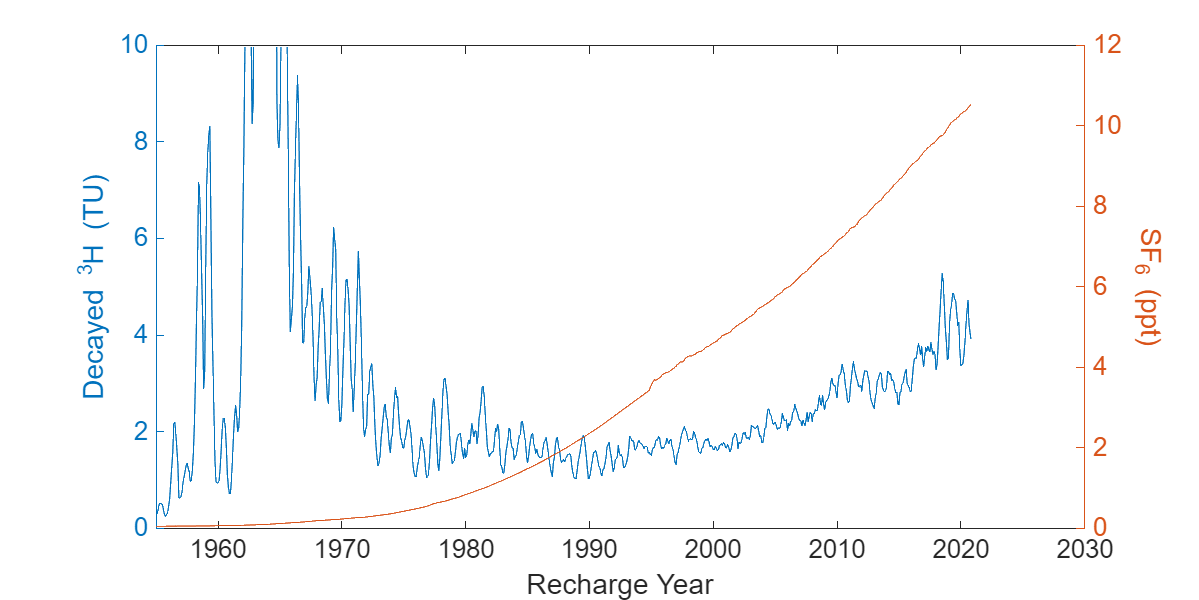

F1 = figure('Position',[100 100 1000 500]); set(gca,'fontsize', 14);
xlabel('Recharge Year')
yyaxis left
plot(Y,TritDecay(1:length(Y))); hold on;
xlim([1955 2030]); ylim([0 10]); ylabel('Decayed ^3H (TU)')
yyaxis right
plot(Y,SF6(1:length(Y))); ylim([0 12]); ylabel('SF_6 (ppt)','Rotation',270);
exportgraphics(F1,"SF6 and 3H Decayed Gilmore.jpg",'Resolution',600); hold off;

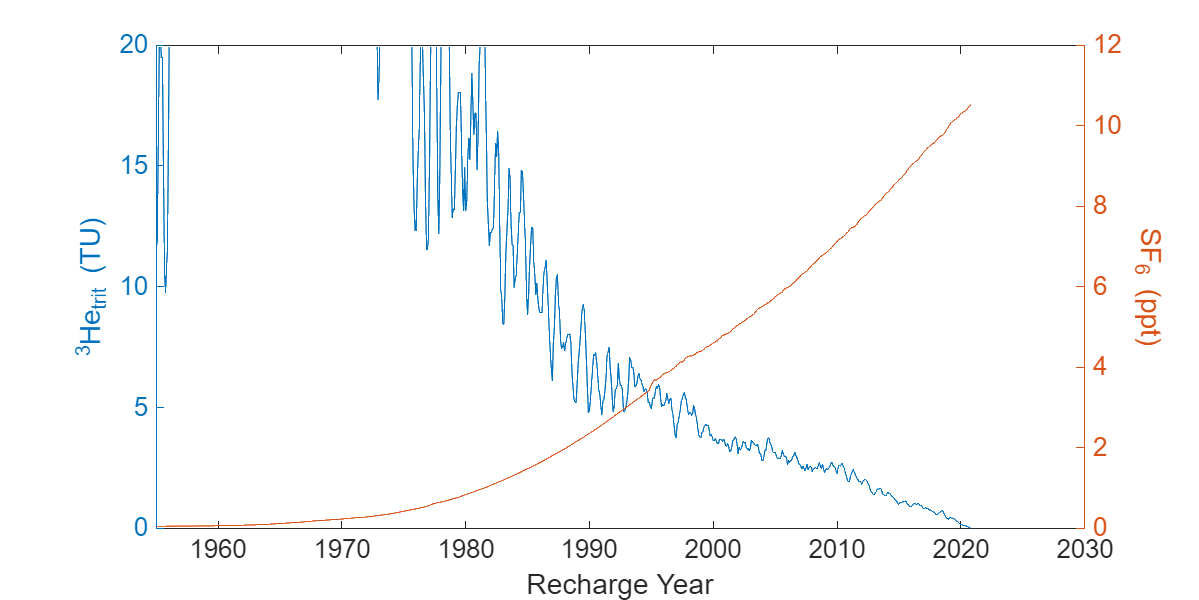

F2 = figure('Position',[100 100 1000 500]); set(gca,'fontsize', 14);
xlabel('Recharge Year')
yyaxis left
plot(Y,HeTrit(1:length(Y))); hold on;
xlim([1955 2030]); ylim([0 20]); ylabel('^3He_t_r_i_t (TU)')
yyaxis right
plot(Y,SF6(1:length(Y))); ylim([0 12]); ylabel('SF_6 (ppt)','Rotation',270);
exportgraphics(F2,"SF6 and 3He Gilmore.jpg",'Resolution',600);

## Convolution Modeling

The following code calculates the transit time distribution (TTD) of the dispersion model for each combination of the mean age and dispersion parameter listed in the variables MA and DP respectively. The TTD is then convoluted with the tracer histories to calculate the modeled tracer concentrations for each mean age - dispersion parameter combination.

f = waitbar(0, 'Starting');
tic
check(1:row,1:col,1) = zeros;
for m = 1:numel(MA)    
for n = 1:numel(DP)
    TTD = (1./MA(m)).*(1./(T'./MA(m))).*(1./(sqrt(4.*pi.*DP(n).*T'./MA(m)))).*exp(-((1-(T'./MA(m))).^2)./(4.*DP(n).*T'./MA(m)));
    TotSF6(n,m,1) = sum(SF6(:,1).*TTD.*TimeStep);
    TotIntTrit(n,m,1) = sum(IntTrit(:,1).*TTD.*TimeStep);
    TotTritDecay(n,m,1) = sum(TritDecay(:,1).*TTD.*TimeStep);
    TotHeTrit(n,m,1) = sum(HeTrit(:,1).*TTD.*TimeStep);
    check(n,m,1) = sum(TTD,1).*TimeStep;
    clear TTD
end
    waitbar(m./numel(MA), f, sprintf('Progress: %d %%', floor(m./numel(MA).*100)));
    pause(0.1);
end 
close(f)

toc

Elapsed time is 954.499441 seconds.



TotTritRatio = TotTritDecay./TotIntTrit;

max(abs(1-check).*100,[],'all')

ans =           123.016109514471


    %The sum for each iteration of NormSeep times the timestep should be 1
    %(100%). This checks to see what the largest percent deviation is. My
    %goal is for the highest percent deviation to be near 1%.

## Chi-Square Error, Heat Maps, and Results Output

The following code calculates the chi-square error for every set of model parameters and selects the model parameters that produces the lowest chi-square error between measured and modeled tracer concentrations. Chi-square heat maps and an output Excel file are also produced.

f = waitbar(0, 'Starting');
TracerstoFit = [1,2,3,4,5]; %Select which tracers to use.
Tlab = ''


Tlab =

  0×0 empty char array




if any(TracerstoFit(:) == 1)
    Tlab = strcat(Tlab,'SF_6,');
end
if any(TracerstoFit(:) == 2)
    Tlab = strcat(Tlab,'^3H_o,');
end
if any(TracerstoFit(:) == 3)
    Tlab = strcat(Tlab,'^3H,');
end
if any(TracerstoFit(:) == 4)
    Tlab = strcat(Tlab,'^3He_t_r_i_t,');
end
if any(TracerstoFit(:) == 5)
    Tlab = strcat(Tlab,'^3H/^3H_o');
end %Creates figure labels and column headings in the Excel output.


ans =      3


for SampNumb = 1:20 %Select samples to evaluate.

ChiSquare(1:numel(DP),1:numel(MA),1:5) = zeros;
    %Pre-allocate variable for Chi-square calculation.

DMDOF = -(sht>1) - (col>1) - (row>1);
for m = TracerstoFit
    if isnan(SampleConc(SampNumb,m)) == 0
        DMDOF = DMDOF + 1; %for degress of freedom calculation
    end
end

for w = 1:sht %Calculates chi-square for the DM.
    DMTraceOut(:,:,1) = TotSF6(:,:,w);
    DMTraceOut(:,:,2) = TotIntTrit(:,:,w);
    DMTraceOut(:,:,3) = TotTritDecay(:,:,w);
    DMTraceOut(:,:,4) = TotHeTrit(:,:,w);
    DMTraceOut(:,:,5) = TotTritRatio(:,:,w);
for m = TracerstoFit
    if isnan(SampleConc(SampNumb,m)) == 0
        ChiSquare(:,:,m) = ((SampleConc(SampNumb,m) - DMTraceOut(:,:,m)).^2)./(SampleError(SampNumb,m).^2);
    else ChiSquare(:,:,m) = 0;
    end
end
ChiSqSum(:,:,w) = sum(ChiSquare,3);

end

DMChiProb = 100-chi2cdf(ChiSqSum,DMDOF).*100;
    %Calculates DM chi-square probability.

DMLowChi = min(ChiSqSum,[],"all");
idx = find(ChiSqSum == min(ChiSqSum,[],"all"));
[rdm,cdm,pagdm] = ind2sub(size(ChiSqSum),idx);
    %Finds chi-square minimum.

DMMod(SampNumb,1) = TotSF6(rdm(1),cdm,pagdm)
DMMod(SampNumb,2) = TotIntTrit(rdm(1),cdm,pagdm);
DMMod(SampNumb,3) = TotTritDecay(rdm(1),cdm,pagdm);
DMMod(SampNumb,4) = TotHeTrit(rdm(1),cdm,pagdm);
DMMod(SampNumb,5) = TotTritRatio(rdm(1),cdm,pagdm);
    %Uses chi-square minimum to find the modeled tracer concentrations for
    %the best-fit DM parameters.

MA3 = repmat(MA',length(DP),1,sht);
DP3 = repmat(DP',1,length(MA),sht);
BestFitMAChi = MA3(ChiSqSum == min(ChiSqSum,[],"all"));
BestFitDPChi = DP3(ChiSqSum == min(ChiSqSum,[],"all"));
    %Uses chi-square minimum to find the best-fit DM parameters.

X = MA';
Y = flipud(DP');
Z = flipud(ChiSqSum);
    %Prepares DM related variables for creating chi-square heat maps.


Piston Flow Model

DMMod =           8.38484369998715


MAPFM =                          0        0.0833333333333333         0.166666666666667                      0.25         0.333333333333333         0.416666666666667                       0.5         0.583333333333333         0.666666666666667                      0.75         0.833333333333333         0.916666666666667                         1          1.08333333333333          1.16666666666667                      1.25          1.33333333333333          1.41666666666667                       1.5          1.58333333333333          1.66666666666667                      1.75          1.83333333333333          1.91666666666667                         2          2.08333333333333          2.16666666666667                      2.25          2.33333333333333          2.41666666666667                       2.5          2.58333333333333          2.66666666666667                      2.75          2.83333333333333          2.91666666666667                         3          3.08333333333333    

ZP =           23.8079773527902          23.4349910974619          23.3580228509199          23.8054588485089          22.4034506801421          21.2314207775425          20.5137525822801          20.2293377403298          19.9874342607553          19.5581316355869          18.9387681601935          18.0023828190613          17.7823845289248          17.3030383744577          17.3974813924112          17.5208098680273           17.248303427558          17.1084840053462          16.3724021880376          15.1910837854707          14.3219180166143           13.328675273822          13.3820279545992          12.7829661220278          11.9686739486388          11.7041420394169          12.4701997068386           14.093797422584          14.0108389192689          11.8520229323417          10.1493537132852          9.27342184599916          9.12508624533339          9.48169993799279          9.18510209425625            8.158772877082          7.77529812914873          7.50511812288282       

ResultFileName = "JensenResultsV19.2.mat"

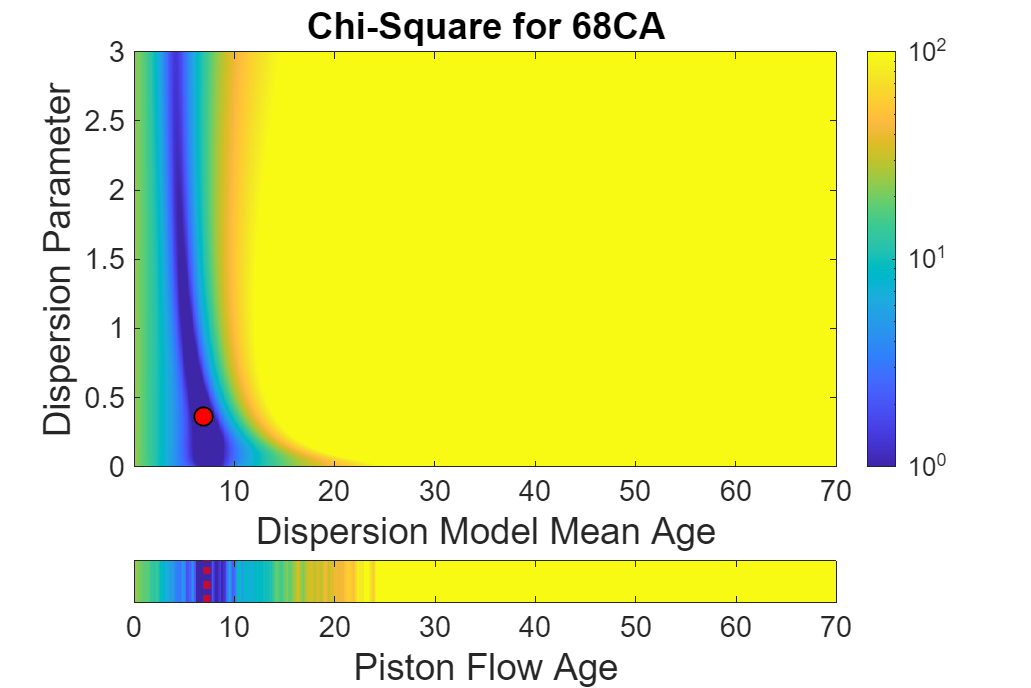

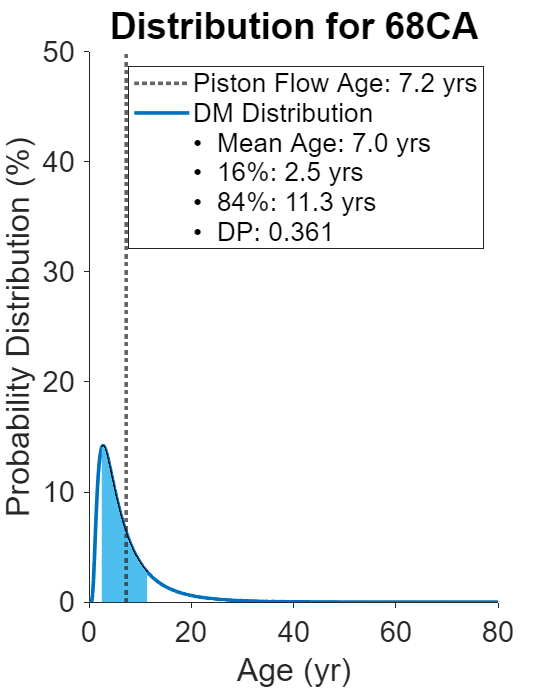

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        35.722       35.508       35.713       36.614       34.708       32.977       31.693       31.042       30.584        30.05        29.41       28.914       29.215       28.676       29.146        29.55       29.332         29.3       28.357       26.691       25.419       23.595       22.756       22.126       21.648       21.756       23.238       25.609       25.543       22.625       20.127       18.562       17.707       17.543       17.098       16.296       15.895       15.551       15.121       14.715       14.328       13.941       13.538       13.138       12.747       12.456       12.222       11.577       11.155       10.795
       35.722       35.508       35.713       36.614       34.708       32.977       31.693       31.042       30.584        30.05        29.41       28.914       29.215       28.676       29.146        29.55       29.332         29.3       28.357       26.691       25.419       23.595       22.756       22.126       21.648       21.756      

ResultFileName = "JensenResultsV19.2.mat"

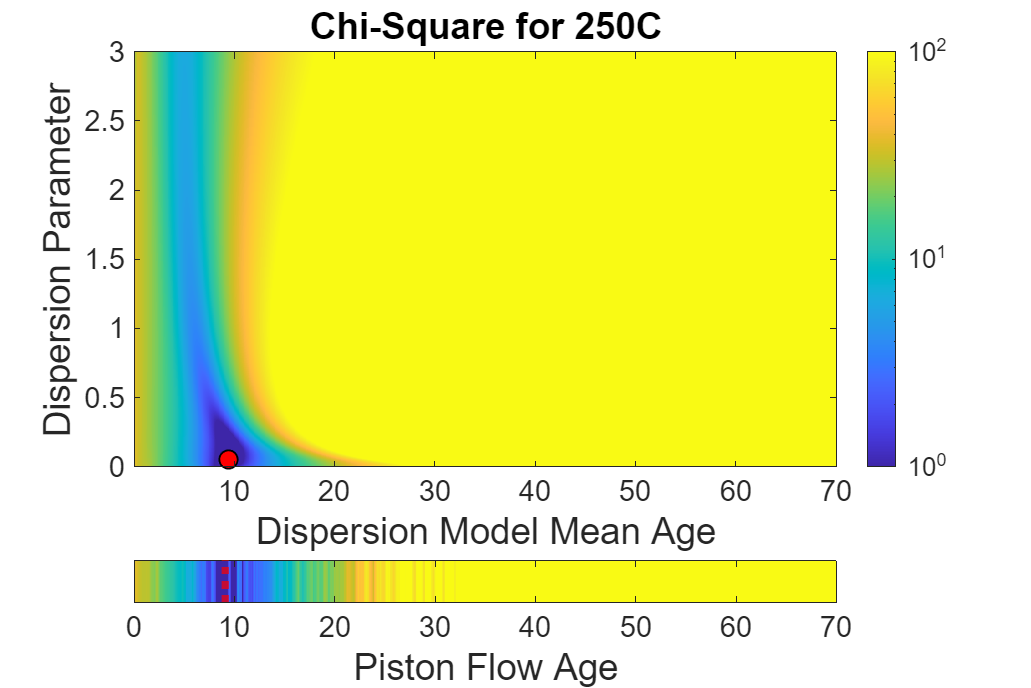

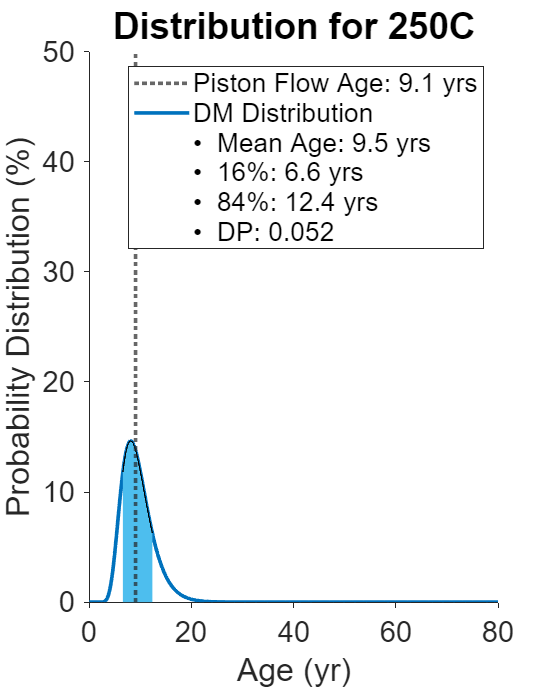

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        164.83       164.07       163.42       163.79       160.64       157.59       155.08       153.58        152.4       151.09       149.59       148.66       148.71       147.38       147.37       147.41       146.82       146.46       144.64       141.71       138.95       135.04        132.1       130.36          129       128.26       129.48        131.9       131.35       127.36       123.75       120.89        118.4       116.72       115.17       113.85       113.05       112.38       111.45        110.3       109.15       108.26       107.06       105.75       104.59       103.11       101.71        100.3       99.145       97.786
       164.83       164.07       163.42       163.79       160.64       157.59       155.08       153.58        152.4       151.09       149.59       148.66       148.71       147.38       147.37       147.41       146.82       146.46       144.64       141.71       138.95       135.04        132.1       130.36          129       128.26      

ResultFileName = "JensenResultsV19.2.mat"

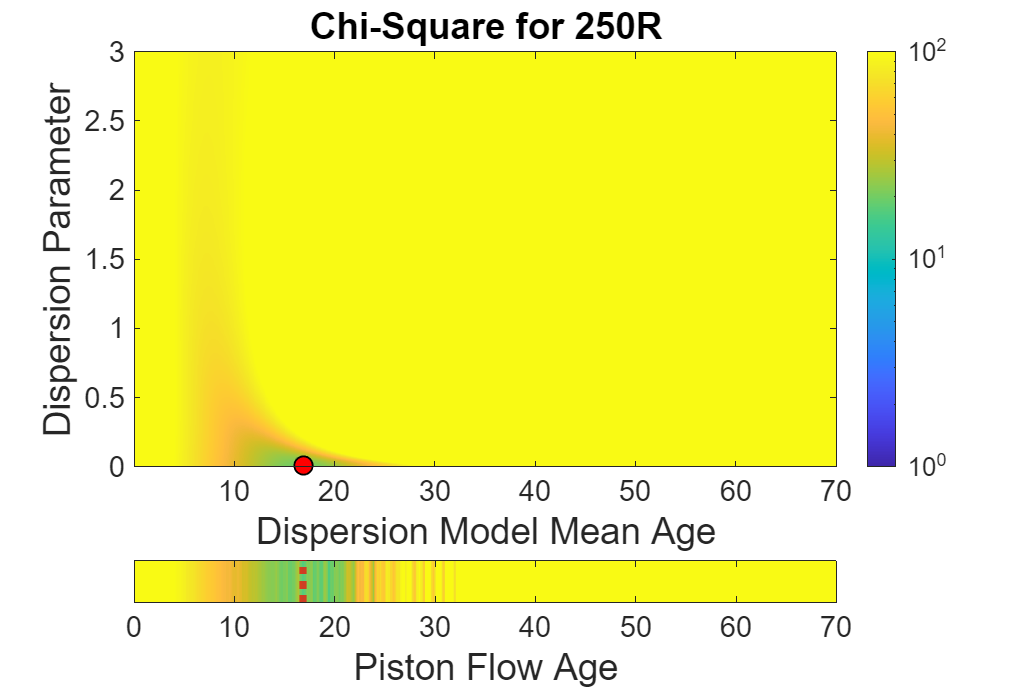

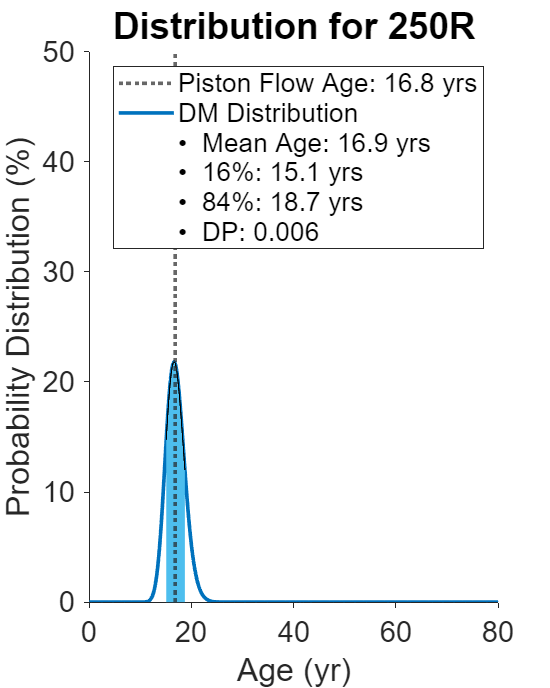

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        18.104       13.433       11.177       12.183       8.9112       6.5854       4.8678       4.8859       6.6027       10.478       17.278       37.759       68.405       85.756       125.67        168.2       203.36       246.55       273.51       278.42       290.11       255.84       201.32       239.53       336.25       453.75       642.33       858.92        954.7       883.55       782.31       692.67       586.81        516.6       549.02       702.87        769.8       812.43       935.09       1026.2       1003.7       1104.2       1193.8       1214.4       1296.5       1219.3       1192.8       1415.4       1629.1       1612.4
       18.104       13.433       11.177       12.183       8.9112       6.5854       4.8678       4.8859       6.6027       10.478       17.278       37.759       68.405       85.756       125.67        168.2       203.36       246.55       273.51       278.42       290.11       255.84       201.32       239.53       336.25       453.75      

ResultFileName = "JensenResultsV19.2.mat"

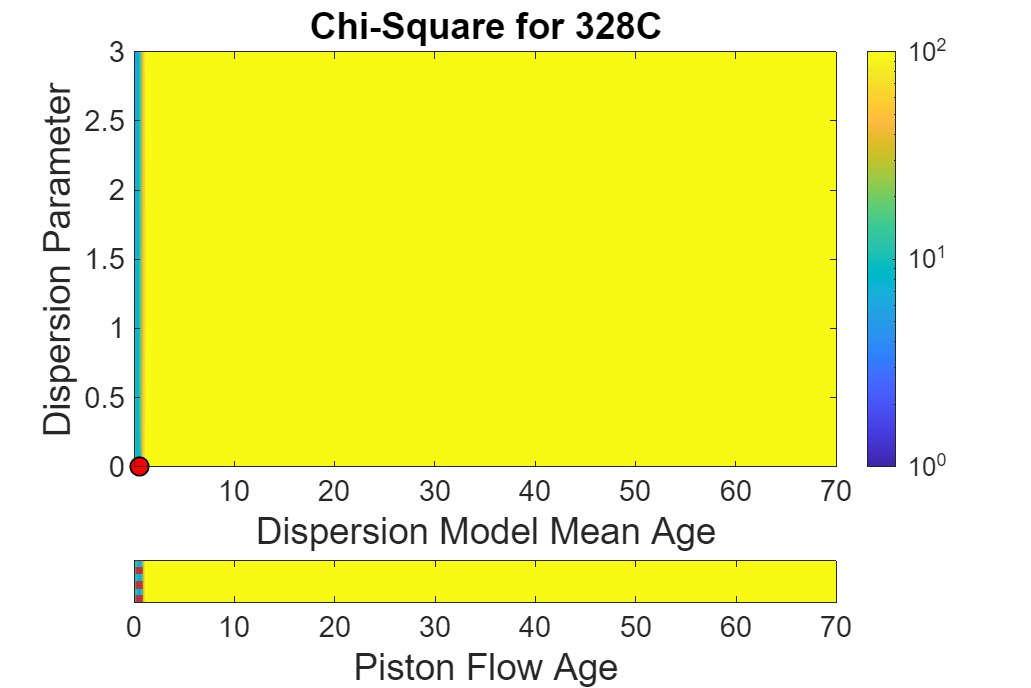

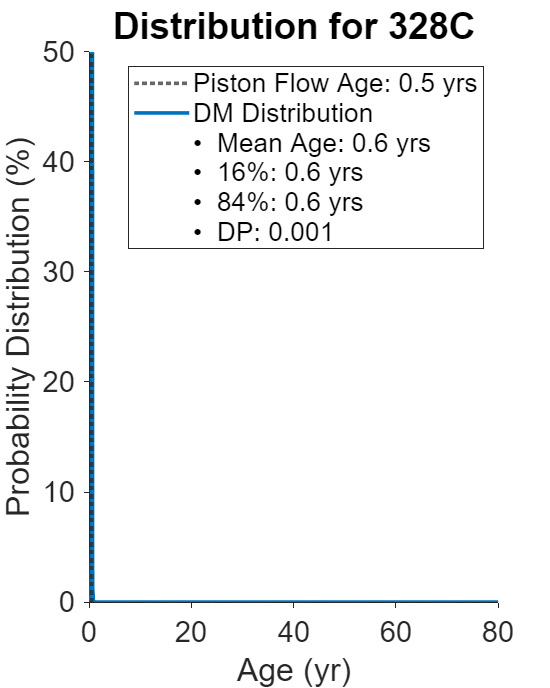

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        17.729        16.58       16.251       16.911       13.291       10.055       7.5095       5.9817       4.9197       3.9897       3.1525       3.2653       4.9943       4.9668        7.638       10.446       12.046       14.465       14.804       12.846       11.926       7.3957       2.9415       4.5167       10.167       18.212       33.178       51.622       58.394       49.347       38.717       30.274       21.789       16.813       18.528       28.234       32.401       34.909       43.176         49.3        47.13        53.96       60.067       61.102       66.706       60.664        58.48       74.251       89.828       88.139
       17.729        16.58       16.251       16.911       13.291       10.055       7.5095       5.9817       4.9197       3.9897       3.1525       3.2653       4.9943       4.9668        7.638       10.446       12.046       14.465       14.804       12.846       11.926       7.3957       2.9415       4.5167       10.167       18.212      

ResultFileName = "JensenResultsV19.2.mat"

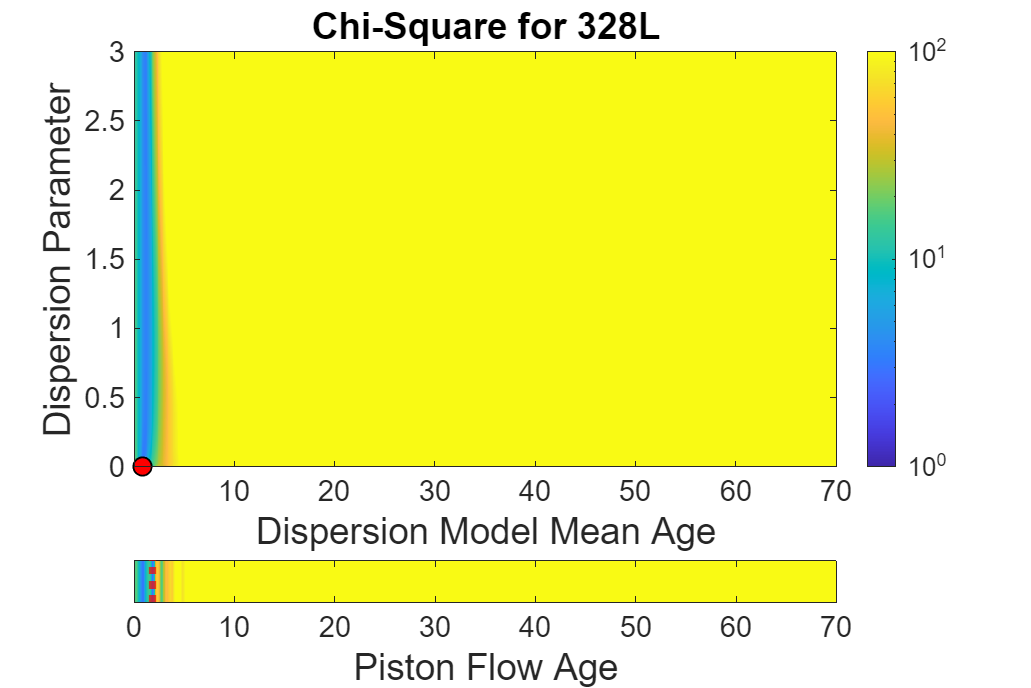

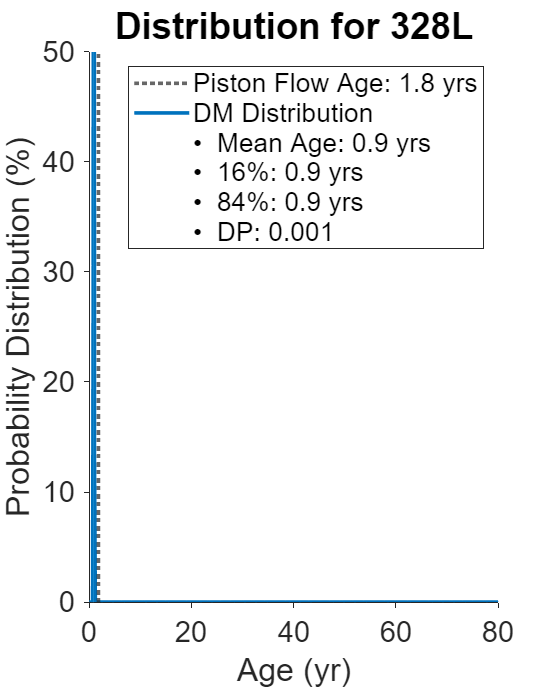

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        1942.7       1933.3       1920.1       1909.9       1895.6         1881       1867.7       1857.9       1848.8       1838.3       1826.4       1816.7       1809.1       1798.3         1789       1781.6         1775       1768.8       1757.6       1743.4       1726.2       1704.5       1683.7         1669       1654.8       1641.1       1632.6       1627.9       1620.3       1609.5       1598.9       1585.8       1569.5       1553.6       1539.9       1530.4         1524       1519.1       1510.8       1500.5       1491.8       1484.1       1473.5       1462.5       1452.3       1439.3         1426       1414.4       1403.4       1391.9
       1942.7       1933.3       1920.1       1909.9       1895.6         1881       1867.7       1857.9       1848.8       1838.3       1826.4       1816.7       1809.1       1798.3         1789       1781.6         1775       1768.8       1757.6       1743.4       1726.2       1704.5       1683.7         1669       1654.8       1641.1      

ResultFileName = "JensenResultsV19.2.mat"

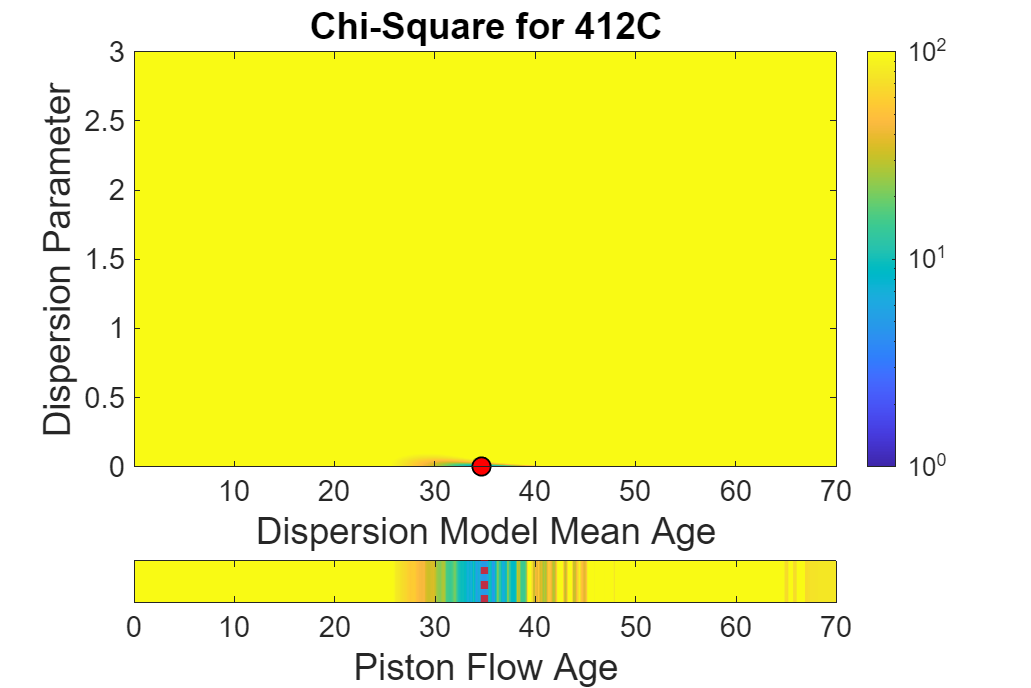

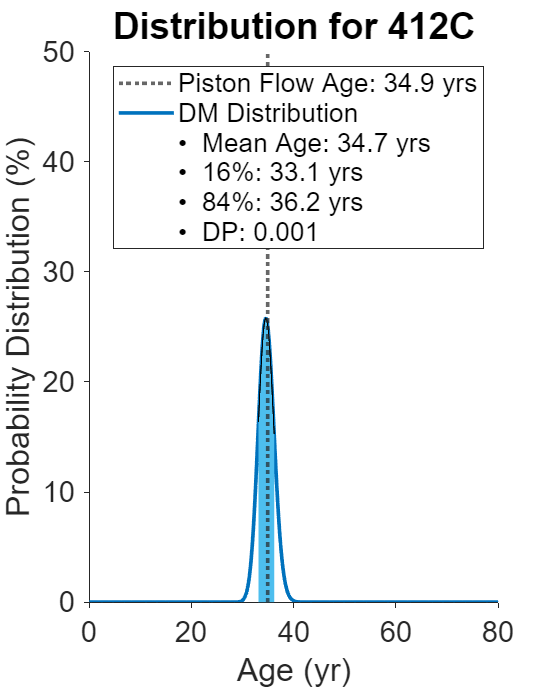

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        1747.4       1738.9       1726.3       1716.3       1704.6       1692.8       1682.3       1674.8       1667.4       1658.4       1647.8       1638.1       1630.3       1620.8       1611.8       1604.8       1599.2       1593.8       1584.3       1572.4       1557.5       1539.2       1521.9       1508.5       1494.6         1481       1471.8       1466.1       1459.4       1451.5       1443.9       1433.6       1420.2       1406.7       1394.5       1385.4       1379.8       1375.9       1368.3         1359       1351.8         1345       1335.4       1325.8       1316.7       1305.6       1293.9       1282.9       1272.6       1262.5
       1747.4       1738.9       1726.3       1716.3       1704.6       1692.8       1682.3       1674.8       1667.4       1658.4       1647.8       1638.1       1630.3       1620.8       1611.8       1604.8       1599.2       1593.8       1584.3       1572.4       1557.5       1539.2       1521.9       1508.5       1494.6         1481      

ResultFileName = "JensenResultsV19.2.mat"

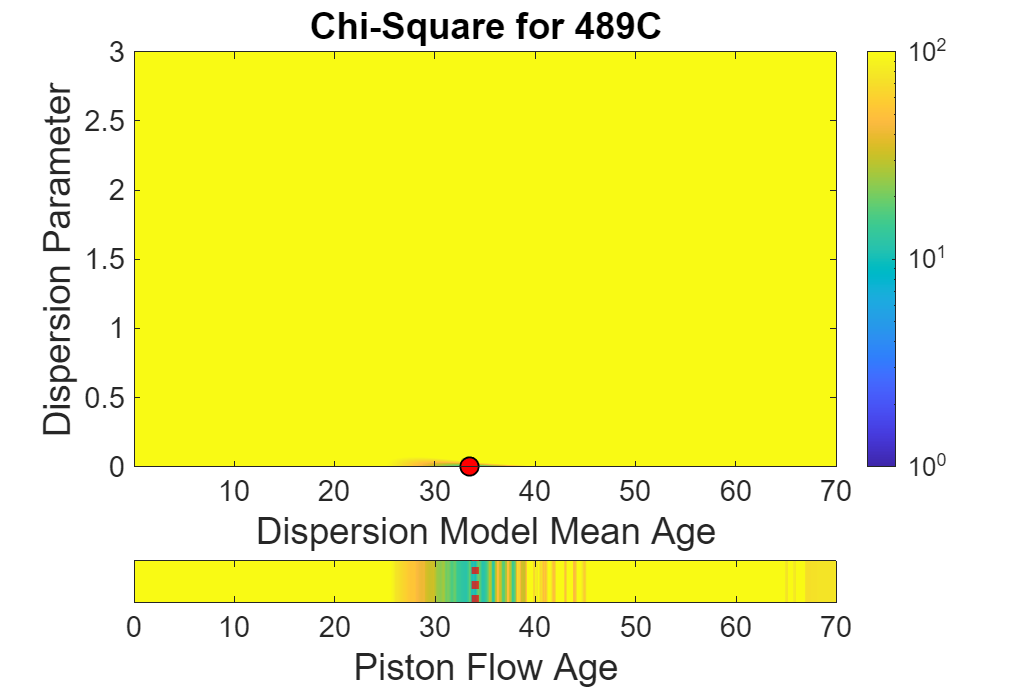

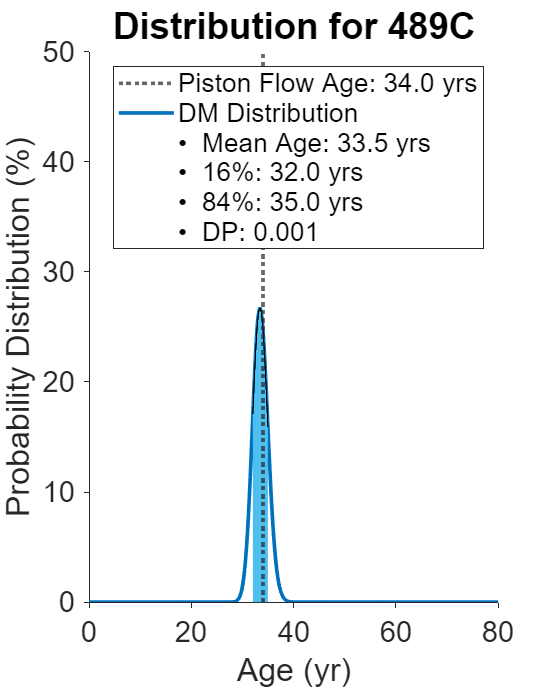

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        501.49       499.29       496.36       494.95       489.55       484.15        479.5       476.49       473.89       470.91       467.48       465.04       463.91       460.82       459.26       458.11        456.6       455.36       451.74       446.48       440.74       432.98       426.22       421.91        418.1       414.93       414.63       416.18       414.46       408.93       403.75       398.71       393.26       388.63       384.67       381.88       380.14       378.81       376.58        373.7       371.09       368.99          366       362.77       359.87       356.03       352.21       348.85       345.85       342.42
       501.49       499.29       496.36       494.95       489.55       484.15        479.5       476.49       473.89       470.91       467.48       465.04       463.91       460.82       459.26       458.11        456.6       455.36       451.74       446.48       440.74       432.98       426.22       421.91        418.1       414.93      

ResultFileName = "JensenResultsV19.2.mat"

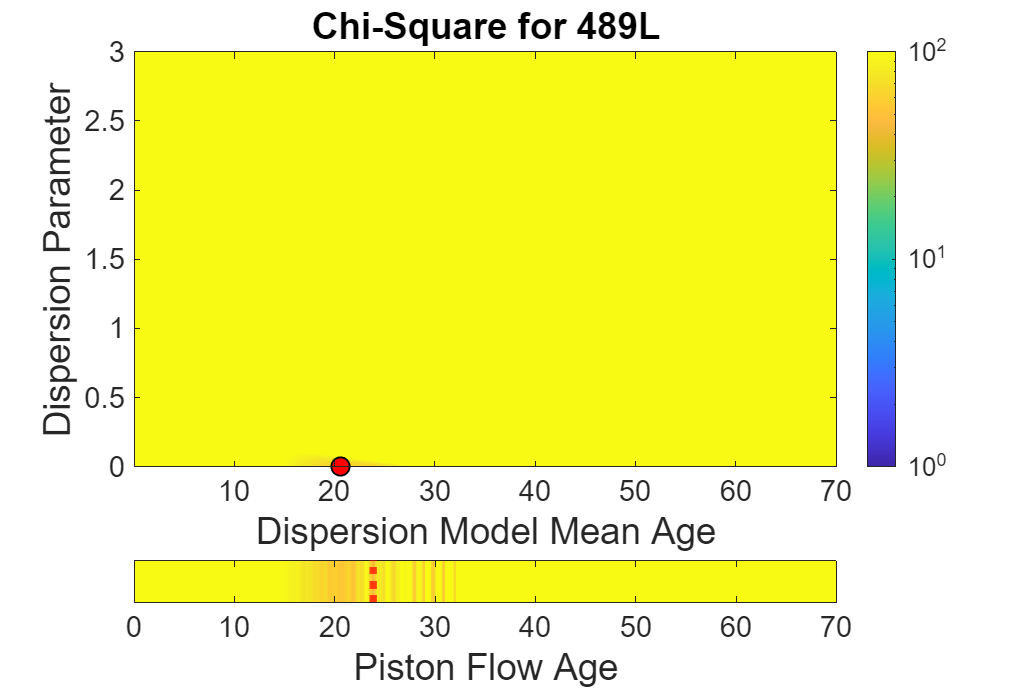

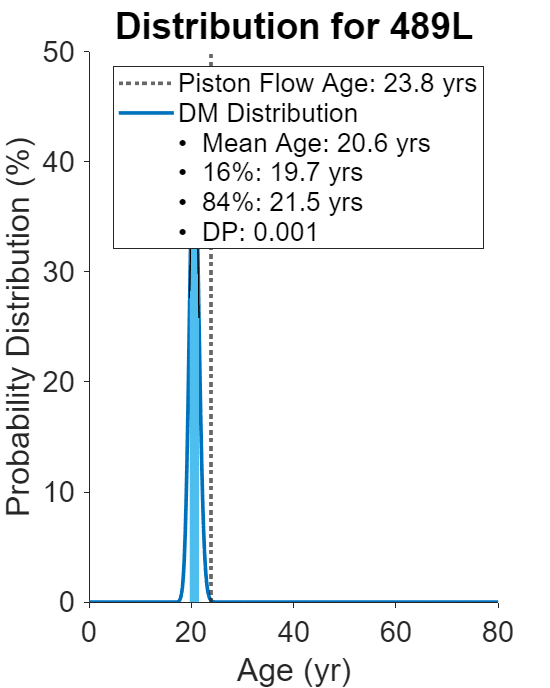

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        656.89       652.72       648.22       645.16       637.63       630.06       623.05        617.6       612.72       607.77       602.65       599.04       596.52       591.67       588.64       585.78       582.34        579.2       573.85       566.89       559.71       550.42       541.75       536.29       531.78       527.79       526.41       526.42       523.01       515.77       508.75       501.97       494.84        488.6       483.44       479.77        476.5       473.49       470.03       465.94       461.77       458.34       454.19        449.7       445.63       440.51       435.54       431.42       427.51       422.94
       656.89       652.72       648.22       645.16       637.63       630.06       623.05        617.6       612.72       607.77       602.65       599.04       596.52       591.67       588.64       585.78       582.34        579.2       573.85       566.89       559.71       550.42       541.75       536.29       531.78       527.79      

ResultFileName = "JensenResultsV19.2.mat"

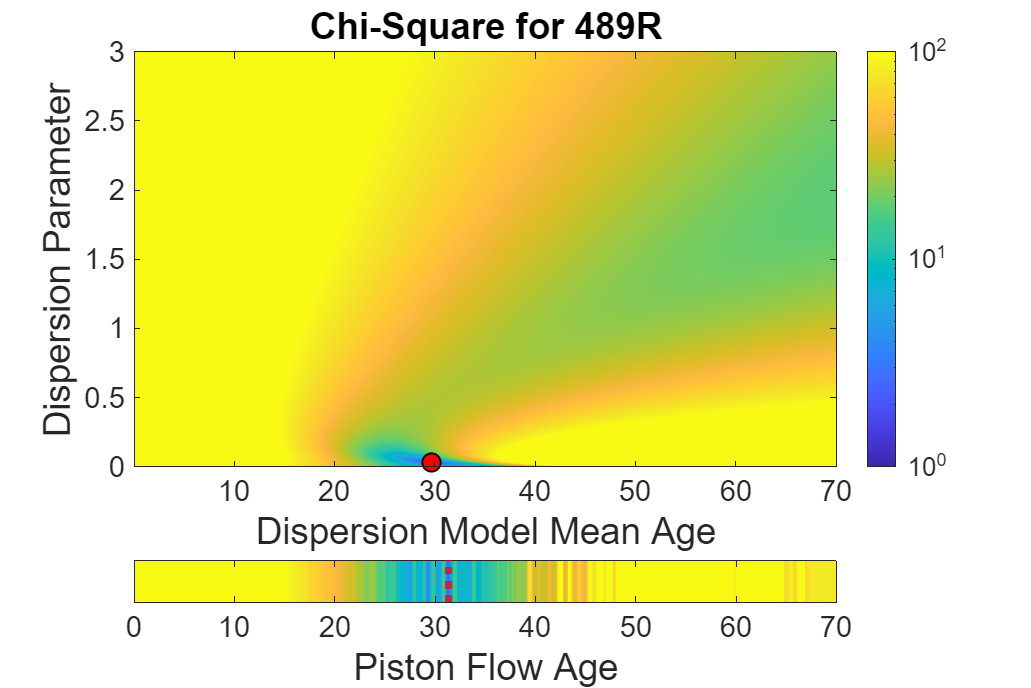

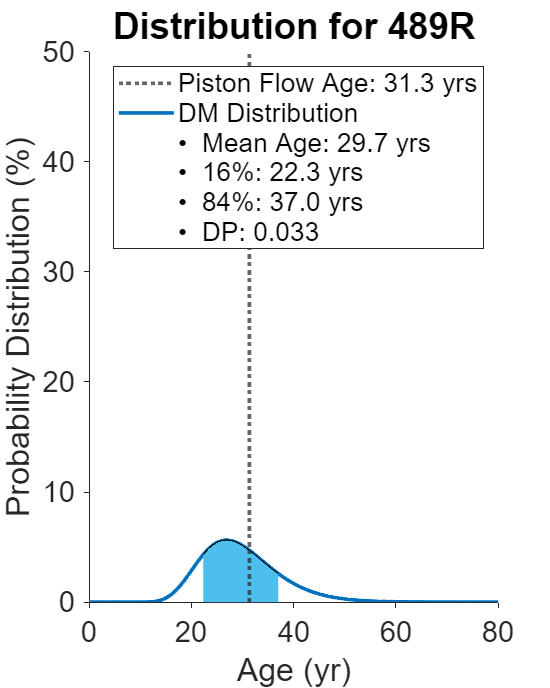

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025            0            0            0            0


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        1.3896       3.1082       7.4529       15.511       19.244       22.775       25.558       29.542       35.357       43.962       56.228       85.764       125.13       147.49       194.54       243.07       282.81       330.43       360.54       367.36       381.06       346.13       288.24       330.42       433.64        555.7       746.63       961.62       1056.5       988.09       889.44       801.25       695.69       624.94       658.35       813.69       880.84       923.58       1045.1       1134.9       1113.3         1212       1299.6         1320         1400       1325.5         1300         1516       1721.8       1706.1
       1.3896       3.1082       7.4529       15.511       19.244       22.775       25.558       29.542       35.357       43.962       56.228       85.764       125.13       147.49       194.54       243.07       282.81       330.43       360.54       367.36       381.06       346.13       288.24       330.42       433.64        555.7      

ResultFileName = "JensenResultsV19.2.mat"

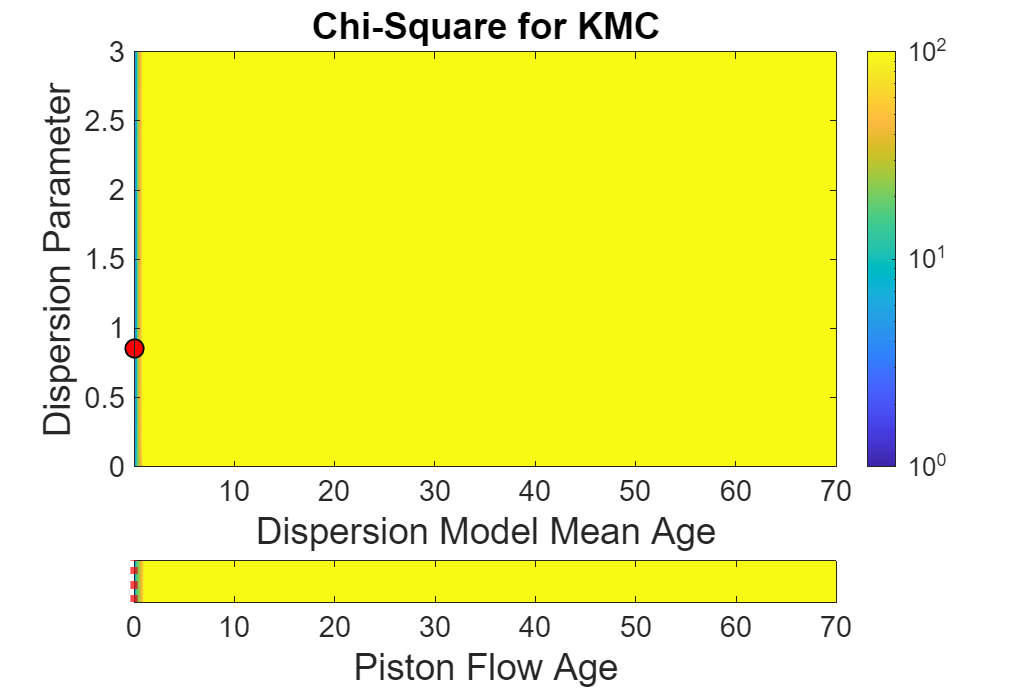

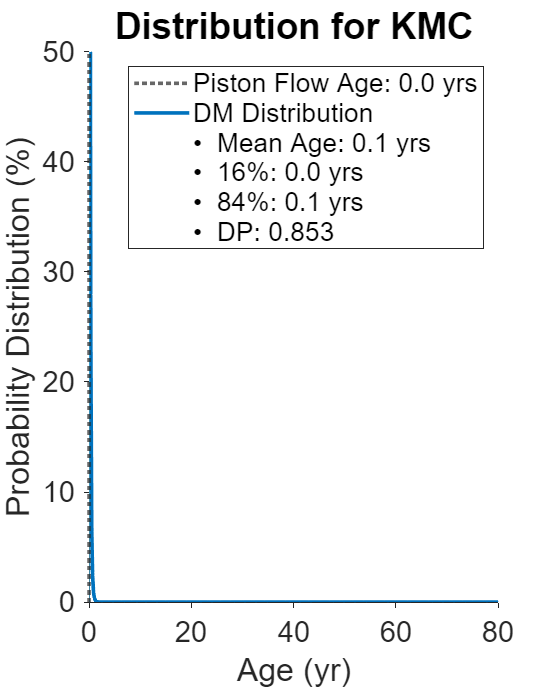

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        1.2383       6.5614       20.905       48.413       69.802       90.064       105.94       124.58       150.01       187.14       239.92       364.64       528.74       624.88          822       1026.4       1196.3       1399.3       1531.1       1566.2       1628.8       1485.8         1241       1422.6       1864.7         2386       3198.4         4112       4519.5         4237       3822.8       3449.8       2999.3       2695.6       2839.9       3509.4       3799.2       3984.2       4507.8       4895.3       4803.6       5229.2       5607.3       5696.4       6041.7       5721.6       5612.2       6543.8       7431.6       7364.9
       1.2383       6.5614       20.905       48.413       69.802       90.064       105.94       124.58       150.01       187.14       239.92       364.64       528.74       624.88          822       1026.4       1196.3       1399.3       1531.1       1566.2       1628.8       1485.8         1241       1422.6       1864.7         2386      

ResultFileName = "JensenResultsV19.2.mat"

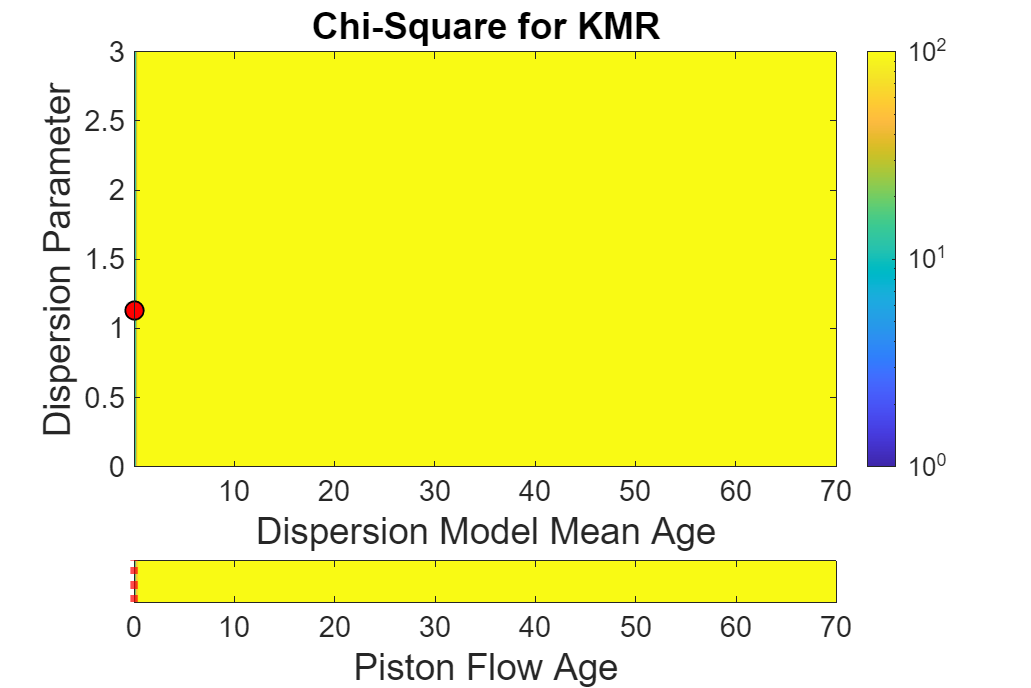

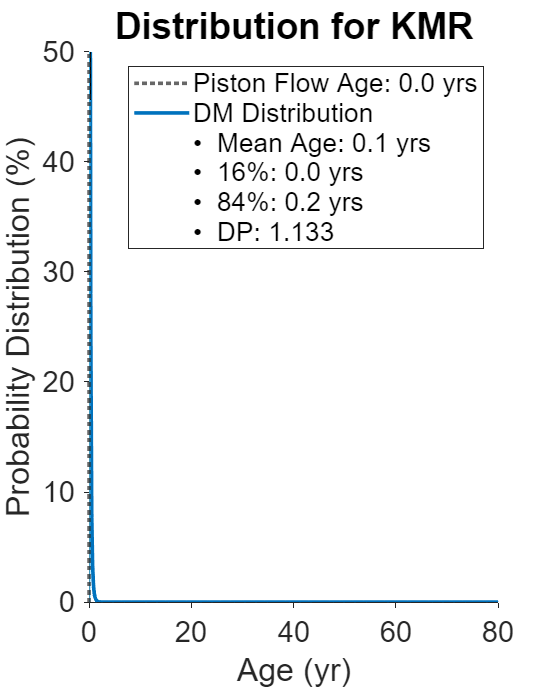

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        194.56       194.34       194.75       196.63       191.96       187.23       182.96       180.25       178.35       176.75        175.3       175.88        177.6       176.14       177.35       178.24       177.75       177.66       175.28       171.02       167.27       161.15       155.75       154.15       154.09       154.74       158.25       162.92       162.45       156.22       150.25        145.4       140.94       137.86       136.06       135.61       134.76       133.84       133.23        132.1       130.21       129.37       128.13       126.37       125.09       122.72       120.72       119.82       119.05       117.13
       194.56       194.34       194.75       196.63       191.96       187.23       182.96       180.25       178.35       176.75        175.3       175.88        177.6       176.14       177.35       178.24       177.75       177.66       175.28       171.02       167.27       161.15       155.75       154.15       154.09       154.74      

ResultFileName = "JensenResultsV19.2.mat"

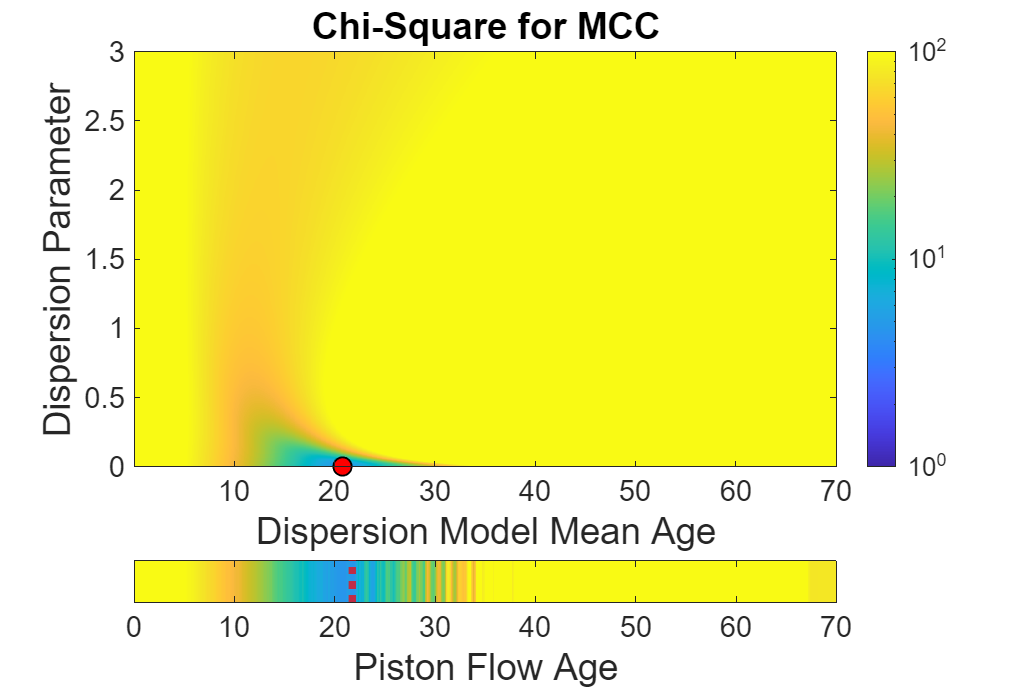

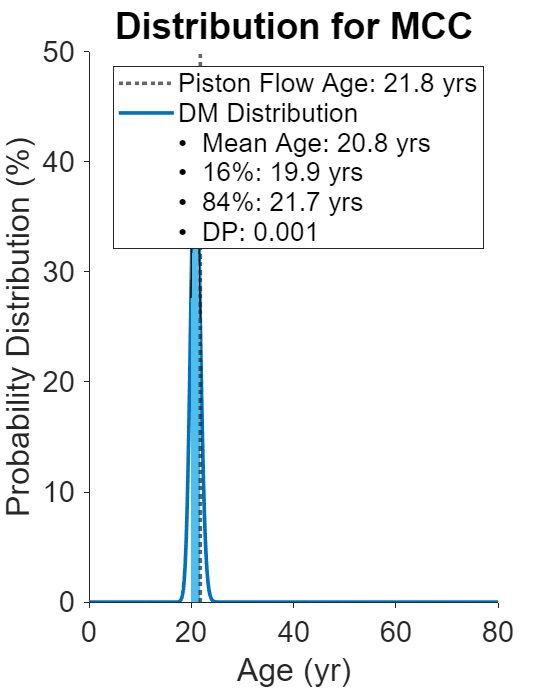

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        791.58       790.13       788.74       790.45       779.69       768.45       757.93       750.98       745.83       741.23       736.84       737.55       740.25       735.89       736.75       737.34       735.75       734.91       728.83       718.62       708.43       692.39        676.8        671.3       669.41       668.46       673.58       681.06       679.07        666.6        654.1       642.45       629.97       619.91       613.85       612.48       610.24       608.02       606.02       602.26        596.9       594.38       590.28       584.76       580.62       572.94       566.05       562.98       560.04       553.88
       791.58       790.13       788.74       790.45       779.69       768.45       757.93       750.98       745.83       741.23       736.84       737.55       740.25       735.89       736.75       737.34       735.75       734.91       728.83       718.62       708.43       692.39        676.8        671.3       669.41       668.46      

ResultFileName = "JensenResultsV19.2.mat"

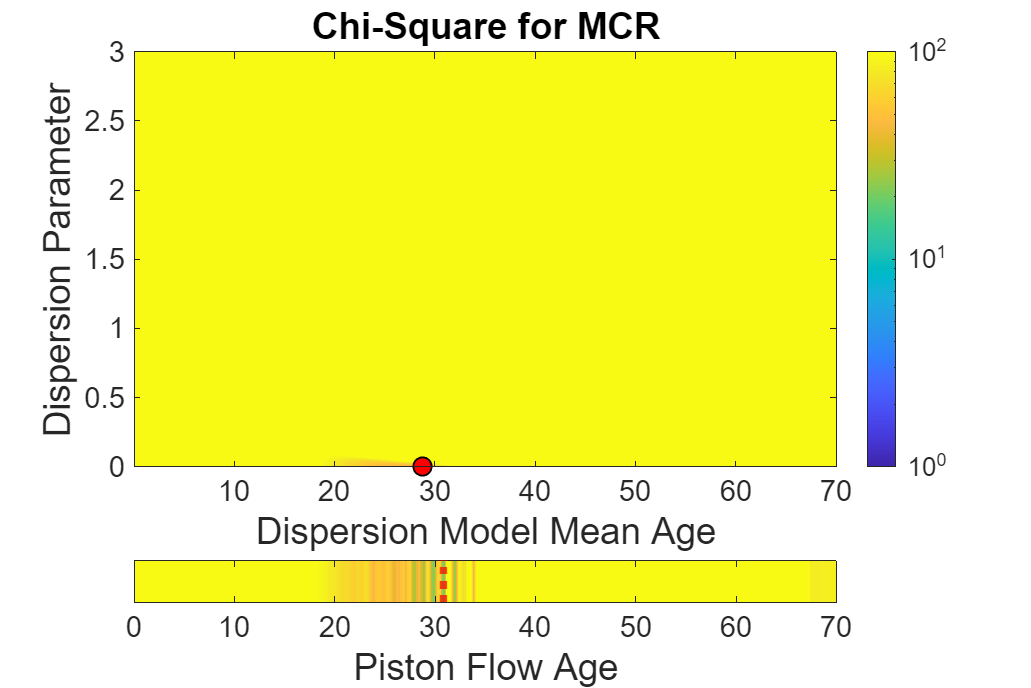

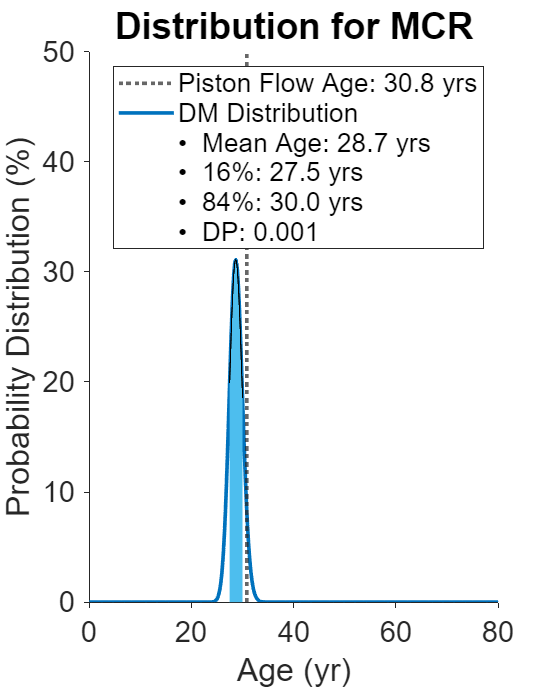

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        505.64       511.04       522.31       539.66       519.08       496.79        474.3       459.22        450.1       445.64       444.58       460.42       479.05       476.23       489.79       499.45       500.22       503.07       494.94       476.87       462.78       433.73       403.19       402.67       415.44       430.01       457.38       486.21       487.05       457.52       426.89       401.48       376.73       359.38       354.94       363.16       362.24       359.01       362.01       361.38       351.97       352.07       350.58       344.32        342.1       330.25       321.92       326.74       330.58       322.77
       505.64       511.04       522.31       539.66       519.08       496.79        474.3       459.22        450.1       445.64       444.58       460.42       479.05       476.23       489.79       499.45       500.22       503.07       494.94       476.87       462.78       433.73       403.19       402.67       415.44       430.01      

ResultFileName = "JensenResultsV19.2.mat"

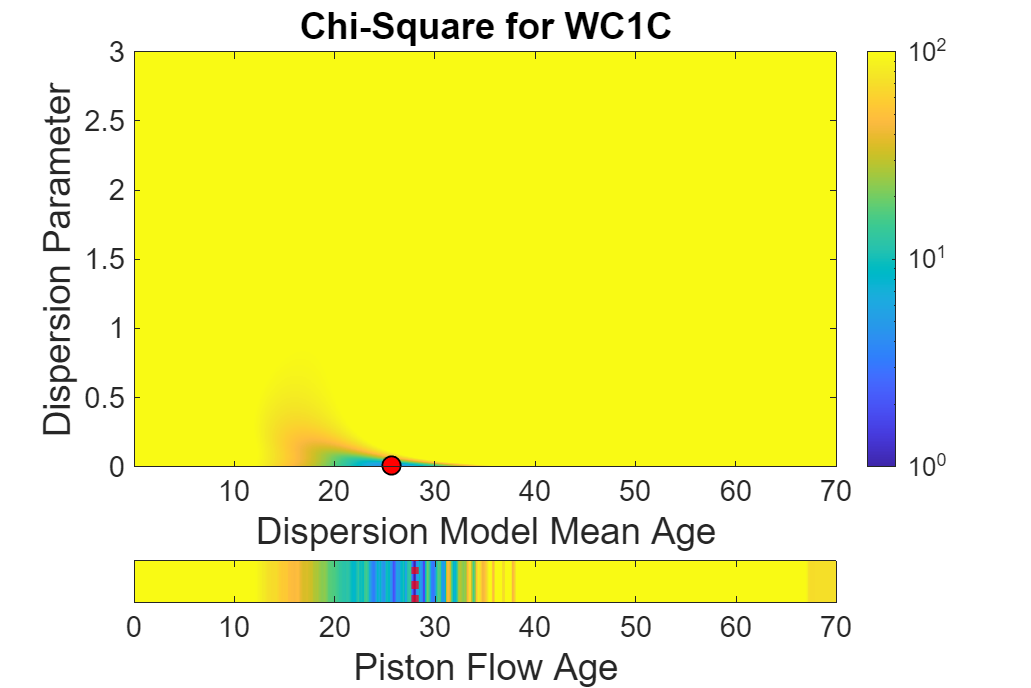

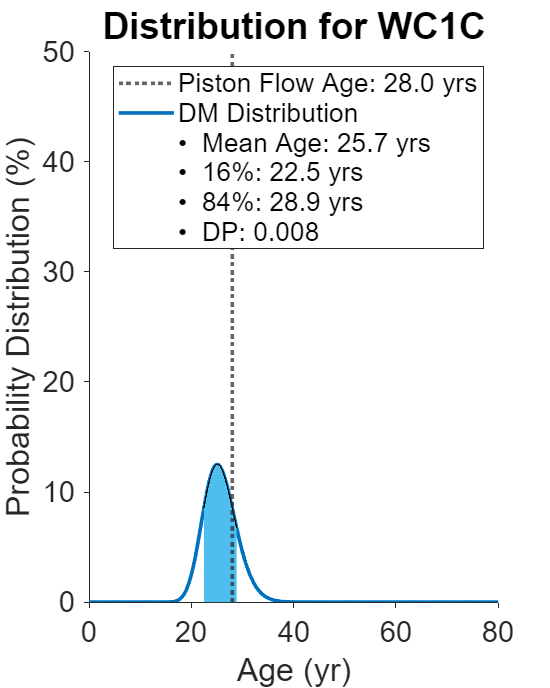

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        122.55       122.02        121.8       122.52       119.64       116.86       114.54       113.14       112.08       110.99        109.8       109.25       109.61       108.53       108.82       109.06       108.58       108.33       106.74        104.1       101.76       98.333       95.782       94.468       93.633       93.373       94.891       97.403       96.963       93.153       89.703       87.073       84.909       83.547        82.35       81.342       80.638        80.01       79.262       78.347       77.353       76.603       75.653        74.59       73.655       72.489       71.422        70.31       69.399       68.323
       122.55       122.02        121.8       122.52       119.64       116.86       114.54       113.14       112.08       110.99        109.8       109.25       109.61       108.53       108.82       109.06       108.58       108.33       106.74        104.1       101.76       98.333       95.782       94.468       93.633       93.373      

ResultFileName = "JensenResultsV19.2.mat"

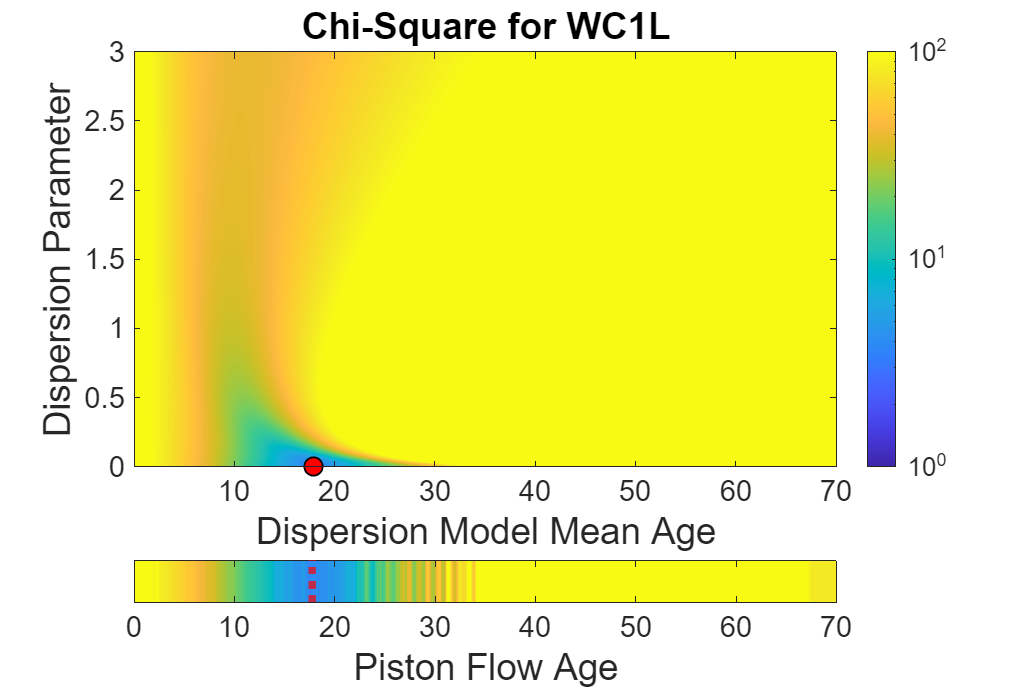

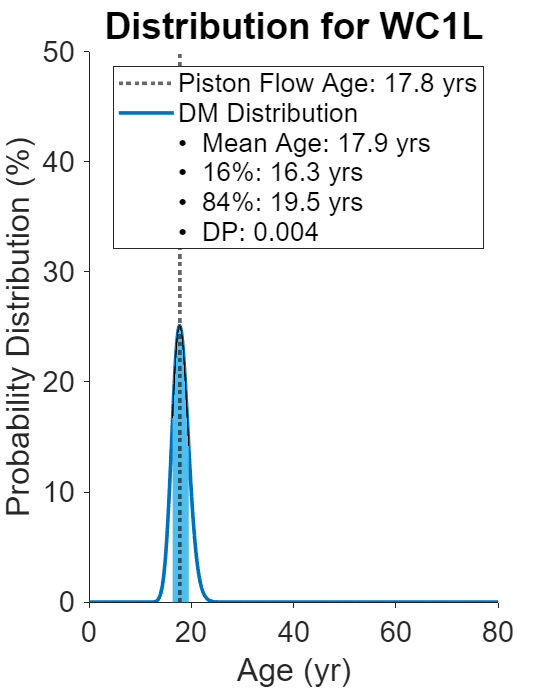

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP =        513.97       511.65        508.7       507.25       501.63       495.98       490.99       487.62       484.73       481.56       478.03       475.72       474.63        471.4        469.8       468.53       466.82       465.39       461.61       456.18       450.32       442.38       435.26       430.94       427.29        424.2       423.86       425.16       423.21       417.57       412.21       406.96       401.27        396.4       392.35       389.61       387.71       386.17       383.84       380.85       378.05       375.81       372.71       369.35       366.34       362.38       358.45       355.05       351.95       348.42
       513.97       511.65        508.7       507.25       501.63       495.98       490.99       487.62       484.73       481.56       478.03       475.72       474.63        471.4        469.8       468.53       466.82       465.39       461.61       456.18       450.32       442.38       435.26       430.94       427.29        424.2      

ResultFileName = "JensenResultsV19.2.mat"

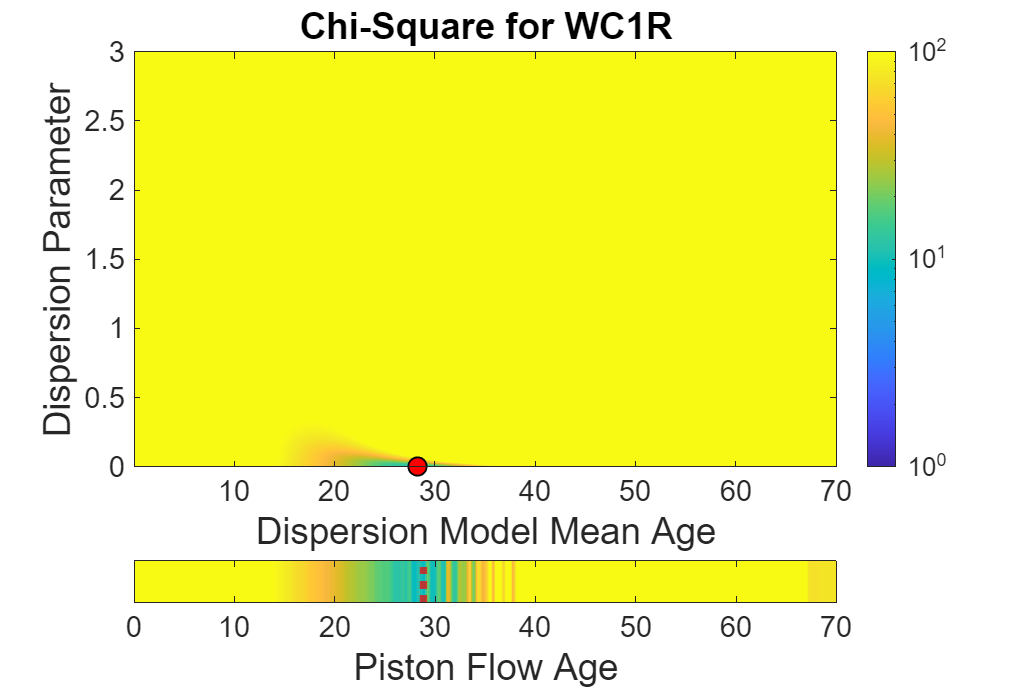

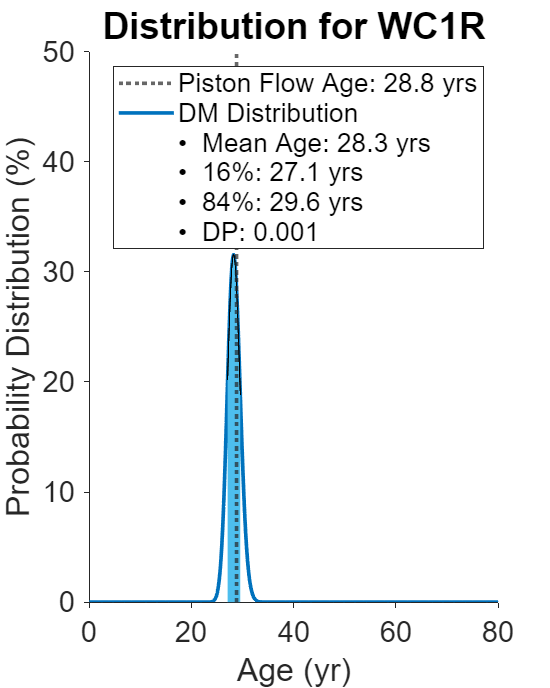

DMMod =        8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM =             0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167          2.5       2.5833       2.6667         2.75       2.8333       2.9167            3       3.0833       3.1667         3.25       3.3333       3.4167          3.5       3.5833       3.6667         3.75       3.8333       3.9167            4       4.0833


ZP = 2×841
          346       344.32       343.01       343.08       337.45       331.76       326.52       322.77       319.75       316.94        314.2       313.32       313.49       310.83       310.49       309.98       308.36        307.1       303.69       298.55       293.72       286.67       280.24       277.36       275.83        274.9       276.61       279.43       277.86       271.39
          346       344.32       343.01       343.08       337.45       331.76       326.52       322.77       319.75       316.94        314.2       313.32       313.49       310.83       310.49       309.98       308.36        307.1       303.69       298.55       293.72       286.67       280.24       277.36       275.83        274.9       276.61       279.43       277.86       271.39


ResultFileName = "JensenResultsV19.2.mat"

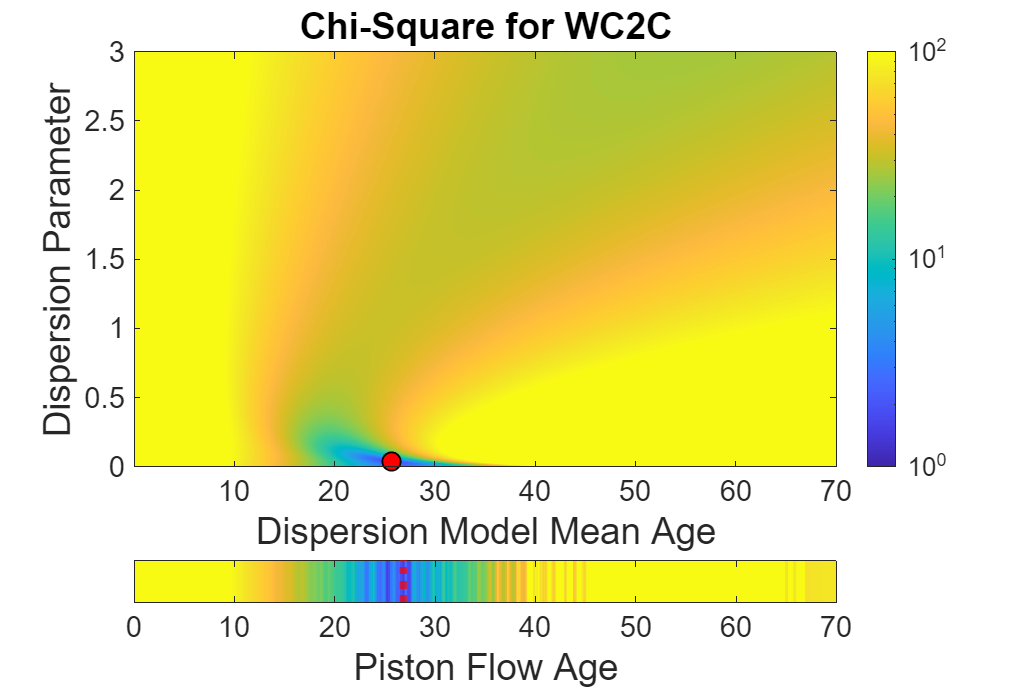

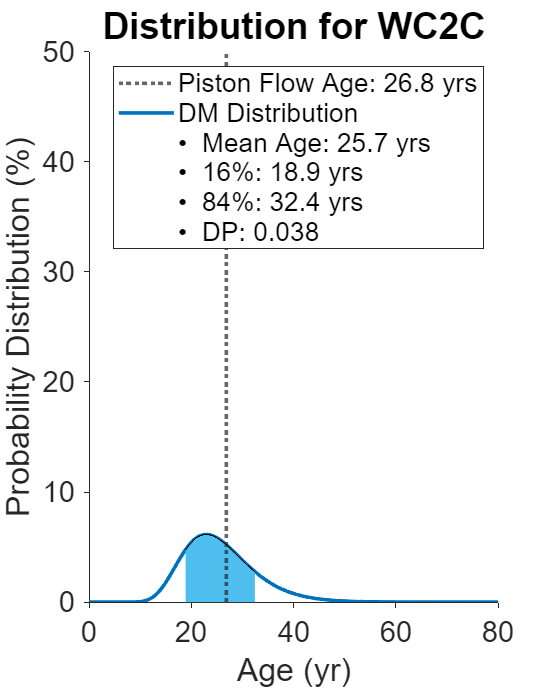

DMMod = 18×5
       8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM = 1×841
            0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167


ZP = 2×841
       115.22       114.19       113.52       113.44       111.07       108.83       106.96        105.6       104.42        103.2        101.9        100.8       100.34       99.154       98.826       98.438       97.537       96.793       95.303       93.219       91.461       89.222       87.733       86.553        85.55       84.992       85.509       86.679       85.925        82.97
       115.22       114.19       113.52       113.44       111.07       108.83       106.96        105.6       104.42        103.2        101.9        100.8       100.34       99.154       98.826       98.438       97.537       96.793       95.303       93.219       91.461       89.222       87.733       86.553        85.55       84.992       85.509       86.679       85.925        82.97


ResultFileName = "JensenResultsV19.2.mat"

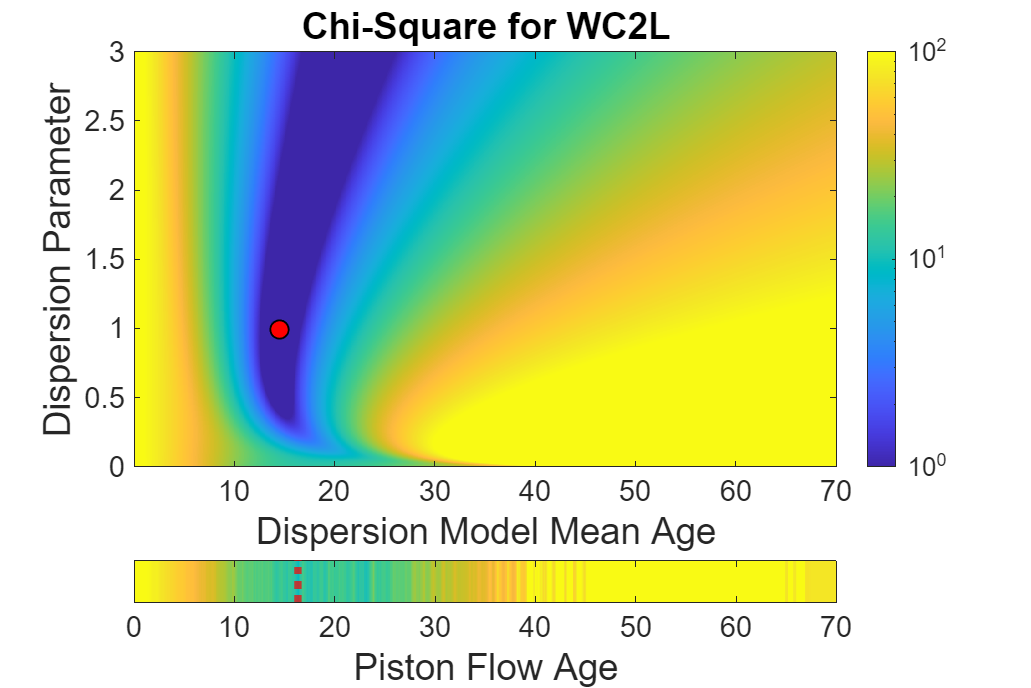

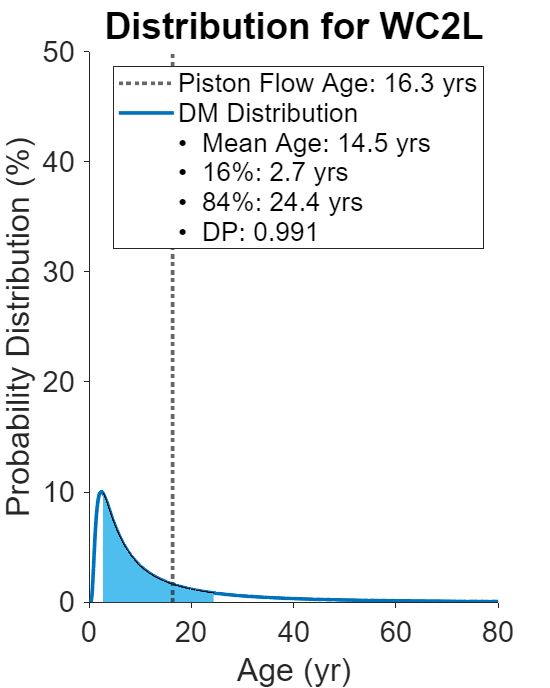

DMMod = 19×5
       8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM = 1×841
            0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167


ZP = 2×841
1.0e+00 *

       4102.4       4094.3       4082.6       4081.7       4041.8       3999.3       3958.7       3931.3       3910.2       3890.6       3871.3       3871.7         3878         3859         3857       3855.3       3848.1       3843.3       3819.1       3780.2       3738.2       3673.5       3607.6       3582.2       3570.2       3560.1       3571.5       3591.3       3581.7       3539.8
       4102.4       4094.3       4082.6       4081.7       4041.8       3999.3       3958.7       3931.3       3910.2       3890.6       3871.3       3871.7         3878         3859         3857       3855.3       3848.1       3843.3       3819.1       3780.2       3738.2       3673.5       3607.6       3582.2       3570.2       3560.1       3571.5       3591.3       3581.7       3539.8


ResultFileName = "JensenResultsV19.2.mat"

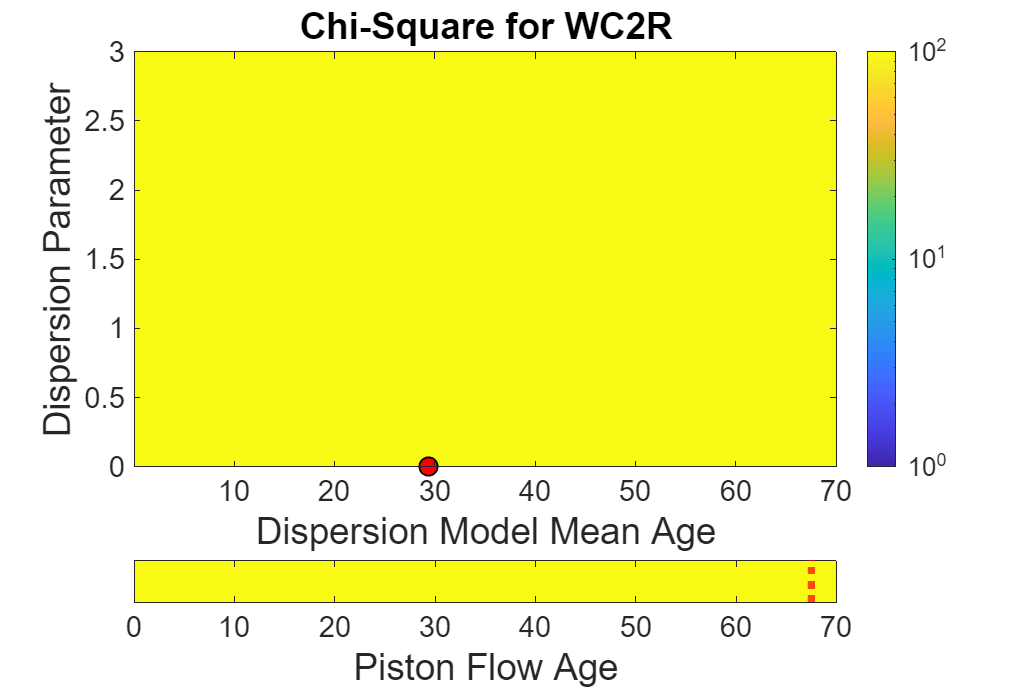

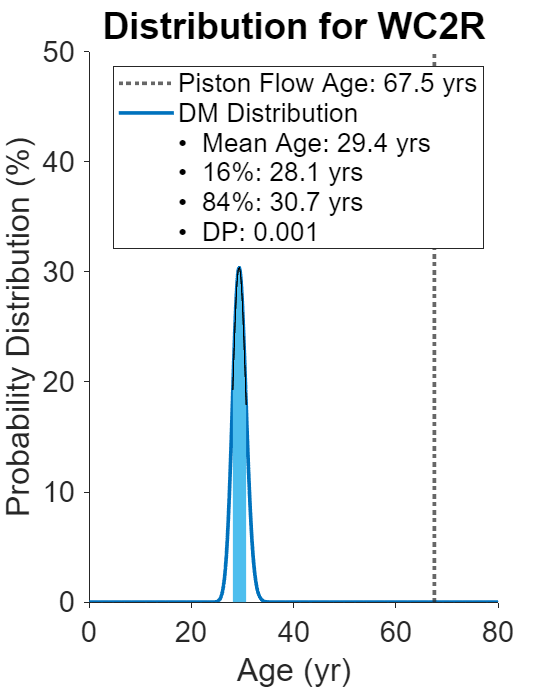

DMMod = 20×5
       8.3848       4.8976       3.2821       1.6155      0.67015
       7.5317       4.8647       2.8563       2.0085      0.58714
       5.4993       5.3099       2.0571       3.2528      0.38741
        10.35       3.7118       3.5921      0.11975      0.96774
        10.26       3.9564        3.757      0.19938      0.94961
       1.6789       11.416       1.6077       9.8085      0.14083
       1.8751       10.127       1.5238       8.6036      0.15046
        4.666       5.4981       1.7244       3.7737      0.31363
       2.8338       11.652       1.7536       9.8983       0.1505
       10.025       3.8733       3.8537     0.019558      0.99495


MAPFM = 1×841
            0     0.083333      0.16667         0.25      0.33333      0.41667          0.5      0.58333      0.66667         0.75      0.83333      0.91667            1       1.0833       1.1667         1.25       1.3333       1.4167          1.5       1.5833       1.6667         1.75       1.8333       1.9167            2       2.0833       2.1667         2.25       2.3333       2.4167


ZP = 2×841
1.0e+00 *

       9435.8       9413.8       9379.6       9365.6       9287.6       9204.4       9124.8       9070.3       9026.7       8984.4         8941       8933.1       8935.4       8893.3       8878.6       8866.7       8848.9       8834.7       8784.4       8707.6       8620.6       8491.7       8359.2       8301.3       8265.2       8230.8       8234.4         8254       8229.3       8156.9
       9435.8       9413.8       9379.6       9365.6       9287.6       9204.4       9124.8       9070.3       9026.7       8984.4         8941       8933.1       8935.4       8893.3       8878.6       8866.7       8848.9       8834.7       8784.4       8707.6       8620.6       8491.7       8359.2       8301.3       8265.2       8230.8       8234.4         8254       8229.3       8156.9


ResultFileName = "JensenResultsV19.2.mat"

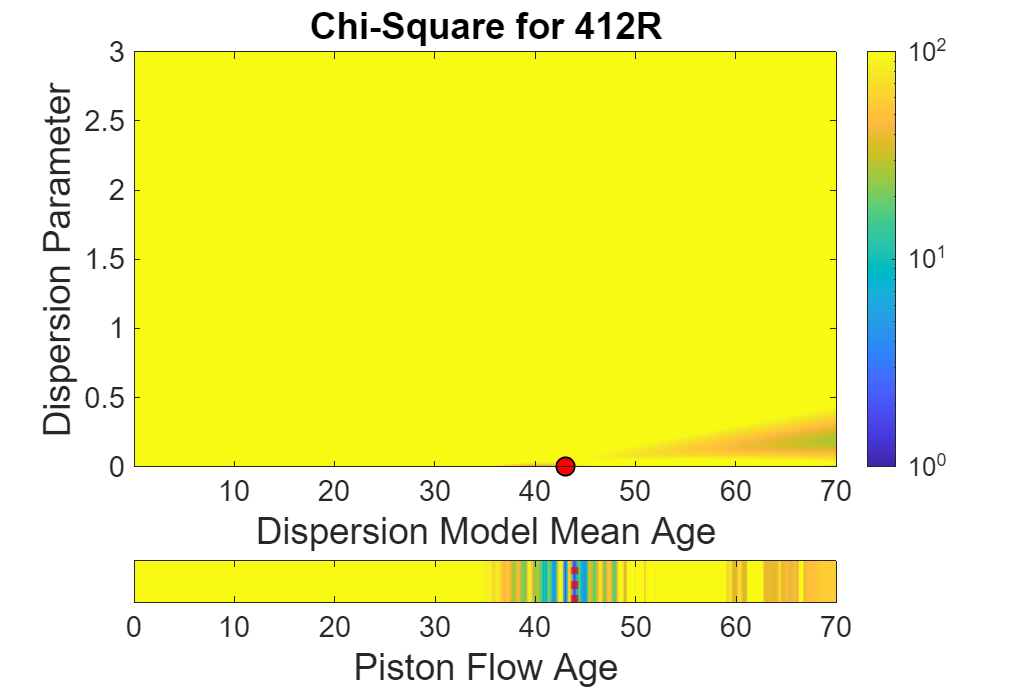

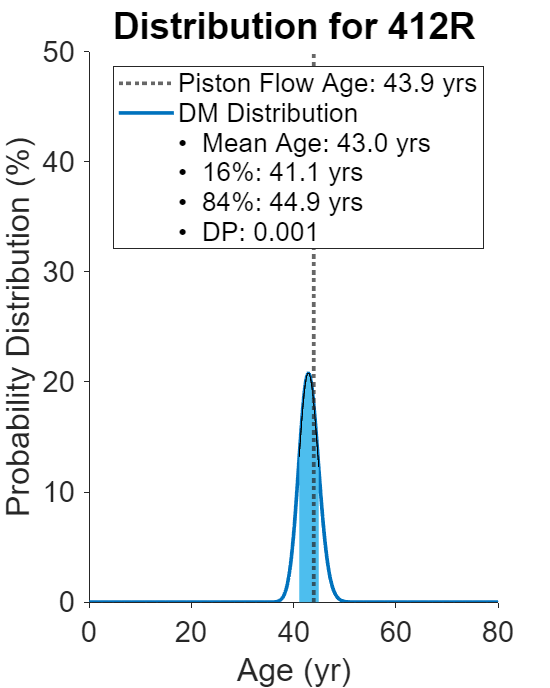

MAPFM = 0:PFMAgeStep:70

for n = 1:numel(MAPFM)
    PFMTraceOut(n,1,w) = SF6(round((MAPFM(n)./TimeStep + 1),0),w);
    PFMTraceOut(n,2,w) = IntTrit(round((MAPFM(n)./TimeStep + 1),0),w);
    PFMTraceOut(n,3,w) = TritDecay(round((MAPFM(n)./TimeStep + 1),0),w);
    PFMTraceOut(n,4,w) = HeTrit(round((MAPFM(n)./TimeStep + 1),0),w);
    PFMTraceOut(n,5,w) = TritRatio(round((MAPFM(n)./TimeStep + 1),0),w);
end
    %Calculates the modeled tracer concentrations for each possible PFM
    %age.

ma3 = (1:1:length(PFMTraceOut))'.*PFMAgeStep - PFMAgeStep;
ma3 = repmat(ma3,1,1,sht);
    %Pre-allocates variables for finding best-fit PFM age.

PFMDOF = -1 -(sht>1);
for m = TracerstoFit
    if isnan(SampleConc(SampNumb,m)) == 0
        PFMDOF = PFMDOF + 1; %for degress of freedom calculation
    end
end

for w = 1:sht
for m = TracerstoFit
    if isnan(SampleConc(SampNumb,m)) == 0
        PFMChiSquare(:,:,m) = ((SampleConc(SampNumb,m) - PFMTraceOut(:,m,w)).^2)./(SampleError(SampNumb,m).^2);
    else PFMChiSquare(:,:,m) = 0;
    end
end
PFMChiSqSum(:,1,w) = sum(PFMChiSquare,3);
end
    %Chi-square calculation for the PFM.

PFMChiProb = 100-chi2cdf(PFMChiSqSum,PFMDOF).*100;
PFMLowChi = min(PFMChiSqSum,[],"all");
PFMChiMaxProb = max(PFMChiProb);
    %Calculation of chi-square probabilities.

idx = find(PFMChiSqSum == min(PFMChiSqSum,[],"all"));
[rpfm,cpfm,pagpfm] = ind2sub(size(PFMChiSqSum),idx);
    %Finds chi-square minimum.   

PFMMod(SampNumb,1) = PFMTraceOut(rpfm(1),1,pagpfm);
PFMMod(SampNumb,2) = PFMTraceOut(rpfm(1),2,pagpfm);
PFMMod(SampNumb,3) = PFMTraceOut(rpfm(1),3,pagpfm);
PFMMod(SampNumb,4) = PFMTraceOut(rpfm(1),4,pagpfm);
PFMMod(SampNumb,5) = PFMTraceOut(rpfm(1),5,pagpfm);
    %Uses chi-square minimum to find the modeled tracer concentrations for
    %the best-fit DPFM age.

BestFitPFM = ma3(PFMChiSqSum == min(PFMChiSqSum,[],"all"));
if length(BestFitPFM) > 1;
    BestFitPFM = BestFitPFM(1)
end
    %Uses chi-square minimum to find the best-fit PFM age.

XP = ma3(:,:,pagpfm(1));
YP = 1:2;
Zop(:,1,1) = PFMChiSqSum(:,:,pagpfm(1));
ZP = Zop';
ZP = repmat(ZP,2,1)
    %Prepares DM related variables for creating chi-square heat maps.

Figure = figure('Position',[100 100 750 500]);
Figs = strcat(Directory,'\',VersionNumb,' Results\Figures\');
ImgN = char(SampleName(SampNumb));
ImgName = strcat(Figs,ImgN,'.jpg');
ImgNameDist = strcat(Figs,ImgN,'Dist.jpg');

subplot(8,1,1:6);
    imagesc(X,Y,Z(:,:,pagdm(1))); set(gca,'fontsize', 16); title("Chi-Square for " + SampleName(SampNumb),FontSize=20);
    c = colorbar; clim([1 100]); hold on; set(gca,'YDir','normal'); shading flat;
    ylabel('Dispersion Parameter','FontSize',20);
    
    xlabel("Dispersion Model Mean Age",'FontSize',20);
    ylim([0 3]); set(gca,'ColorScale','log');
    plot(BestFitMAChi,BestFitDPChi,"Marker","o","MarkerSize",10,"Color",'r','MarkerEdgeColor','k','LineWidth',1,'MarkerFaceColor','r');
    hold on;
subplot(8,1,8);
    imagesc(XP,YP,ZP); set(gca,'fontsize', 16);
    c = colorbar; clim([1 100]); set(c,'Visible','off'); set(gca,'YDir','normal'); shading flat;
    xlabel("Piston Flow Age",'FontSize',20);
    xlim([0 70]); ylim([1 2]); set(gca,'ColorScale','log');
    xline(BestFitPFM,':',Color=[1 0 0],LineWidth=4); yticks([]); hold on; hold off;
exportgraphics(Figure,ImgName,'Resolution',600)

if study == 1
    ResultFileName = strcat('GilmoreResults',VersionNumb,'.mat')
    if isfile(ResultFileName)
        load ResultFileName
    else
        save ResultFileName
    end
elseif study == 2
    ResultFileName = strcat('GilmoreResults',VersionNumb,'.mat')
    if isfile(ResultFileName)
        load ResultFileName
    else
        save ResultFileName
    end
elseif study == 3
    ResultFileName = strcat('JensenResults',VersionNumb,'.mat')
    if isfile(ResultFileName)
        load ResultFileName
    else
        save ResultFileName
    end
end


Results(SampNumb,1) = BestFitPFM;
Results(SampNumb,2) = 0;
Results(SampNumb,3) = PFMLowChi;
Results(SampNumb,4) = PFMDOF;
Results(SampNumb,5) = 100-chi2cdf(Results(SampNumb,3),Results(SampNumb,4)).*100;
Results(SampNumb,6) = BestFitMAChi;
Results(SampNumb,7) = BestFitDPChi;
Results(SampNumb,8) = 0;
Results(SampNumb,9) = DMLowChi;
Results(SampNumb,10) = DMDOF;
Results(SampNumb,11) = 100-chi2cdf(Results(SampNumb,9),Results(SampNumb,10)).*100;

NormSeepDM = (1./BestFitMAChi).*(1./(T'./BestFitMAChi)).*(1./(sqrt(4.*pi.*BestFitDPChi.*T'./BestFitMAChi))).*exp(-((1-(T'./BestFitMAChi)).^2)./(4.*BestFitDPChi.*T'./BestFitMAChi));

CumNormSeepDM = cumsum(NormSeepDM).*TimeStep;

DMAgeRange = T(CumNormSeepDM >= 0.16 & CumNormSeepDM <= 0.84);
if numel(DMAgeRange) > 0
    NSeepRange = NormSeepDM(CumNormSeepDM >= 0.16 & CumNormSeepDM <= 0.84);
    DMAgeRangeEnds = DMAgeRange(:,[1 end]);
    DMRange = DMAgeRange(end) - DMAgeRange(1);
    Results(SampNumb,12:13) = DMAgeRangeEnds;
    Results(SampNumb,14) = DMRange;
else
    a = NormSeepDM(CumNormSeepDM <= 0.16);
    NSeepRange(1) = a(end);
    a = NormSeepDM(CumNormSeepDM >= 0.84);
    NSeepRange(2) = a(1);
end

for z = 1:10
RangeYear = CumNormSeepDM(Age' >= (BestFitPFM - z./2) & Age' <= (BestFitPFM + z./2));
RangeYearAmount(:,z) = RangeYear(end) - RangeYear(1);
Results(SampNumb,14+z) = RangeYearAmount(:,z);
end
if (Results(SampNumb,9) - Results(SampNumb,3)) < 0
    BestModFit = 'DM ';
elseif (Results(SampNumb,9) - Results(SampNumb,3)) > 0
    BestModFit = 'PFM';
end
BestMod(SampNumb,:) = BestModFit;



if study == 1
    GilmoreResults(SampNumb,:) = Results(SampNumb,:);
    filenameR = strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.mat');
    save(filenameR,"GilmoreResults")
elseif study == 2
    GilmoreResults(SampNumb,:) = Results(SampNumb,:);
    filenameR = strcat(VersionNumb,' Results\GilmoreResults',VersionNumb,'.mat');
    save(filenameR,"GilmoreResults")
elseif study == 3
    JensenResults(SampNumb,:) = Results(SampNumb,:);
    filenameR = strcat(VersionNumb,' Results\JensenResults',VersionNumb,'.mat');
    save(filenameR,"JensenResults")
end

writematrix(Results,filename,'Range','B2');
writematrix(BestMod,filename,'Range','Z2');
writematrix(PFMMod,filename,'Range','AA2');
writematrix(DMMod,filename,'Range','AF2')
writecell({'PFM Age','PFM UZ','Chi-Square','PFM DOF','PFM Prob','DM Mean Age','Disp Par','DM UZ','DM Chi-Square', ...
    'DM DOF','DM Prob','DM Low 90% Age','DM High 90% Age','DM Age Range','1 year range amount','2 year range amount', ...
    '3 year range amount','4 year range amount','5 year range amount','6 year range amount','7 year range amount', ...
    '8 year range amount','9 year range amount','10 year range amount','Best Fit Model','PFM SF6','PFM 3Ho','PFM 3H', ...
    'PFM 3He','PFM H/3Ho','DM SF6','DM 3Ho','DM 3H','DM 3He','DM H/3Ho'},filename,'Range','B1');
writecell({'Sample ID'},filename,'Range','A1');
writecell(SampleName,filename,'Range','A2');
format shortG

Figure = figure('Position',[100 100 400 500]); set(gca,'TickDir','out');set(gca,'fontsize', 16);
xline(BestFitPFM,':','LineWidth',2); hold on; title("Distribution for " + SampleName(SampNumb),FontSize=20);
xlim([0 80]); plot(T',NormSeepDM.*100,"LineWidth",2); ylabel('Probability Distribution (%)');
ylim([0 50]); xlabel('Age (yr)')
plot(-1,-1,"Color","w"), plot(-1,-1,"Color","w"), plot(-1,-1,"Color","w"), plot(-1,-1,"Color","w"),

if numel(DMAgeRange)>0
    legend({"Piston Flow Age: " + sprintfc('%0.1f',BestFitPFM) + " yrs","DM Distribution",char(8226) + "  Mean Age: " + sprintfc('%0.1f',BestFitMAChi) + " yrs", ...
    char(8226) + "  16%: " + sprintfc('%0.1f',DMAgeRange(1)) + " yrs",char(8226) + "  84%: " + sprintfc('%0.1f',DMAgeRange(end)) + " yrs", ...
    char(8226) + "  DP: " + BestFitDPChi});
    area(DMAgeRange,NSeepRange.*100,HandleVisibility="off")
else
    legend({"Piston Flow Age: " + sprintfc('%0.1f',BestFitPFM) + " yrs","DM Distribution",char(8226) + "  Mean Age: " + sprintfc('%0.1f',BestFitMAChi) + " yrs", ...
    char(8226) + "  16%: NA",char(8226) + "  84%: NA", char(8226) + "  DP: " + BestFitDPChi});
end
exportgraphics(Figure,ImgNameDist,'Resolution',600)
waitbar(SampNumb./numel(SampNumb), f, sprintf('Progress: %d %%', floor(SampNumb./numel(SampNumb).*100)));
pause(0.1);

end 

close(f)

## Additional Figures

Once results have been generated for all samples, the following code can be used to recreate summary figures found in the main manuscript.

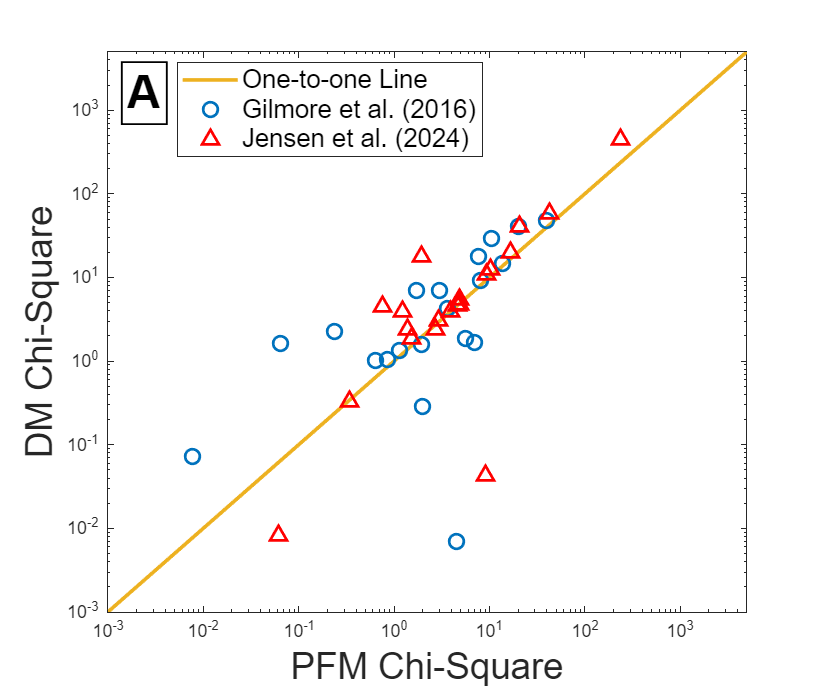

load(strcat(Directory,'\',VersionNumb,' Results\JensenResults',VersionNumb,'.mat'))
load(strcat(Directory,'\',VersionNumb,' Results\GilmoreResults',VersionNumb,'.mat'))
OneTo1 = [0.001 5000];

Figure3 = figure('Position',[100 100 600 500]);
plot([0.001 5000],[0.001 5000],'-',LineWidth=2,Color=[0.9290 0.6940 0.1250]); hold on
plot(GilmoreResults(1:20,3),GilmoreResults(1:20,9),'o',MarkerSize=8,Color=[0 0.4470 0.7410],LineWidth=1.5); 
plot(JensenResults(:,3),JensenResults(:,9),'^',MarkerSize=8,MarkerEdgeColor='r',LineWidth=1.5)
% plot(OneTo1,OneTo5PerUp,'--'); plot(OneTo1,OneTo5PerLow,'--')
text(0.0016,1600,'A','FontSize',25,'EdgeColor','k','FontWeight','bold','LineWidth',1)
xlabel("PFM Chi-Square",'FontSize',20); ylabel("DM Chi-Square",'FontSize',20);
xlim([0.001 5000]); xticks([0.001 0.01 0.1 1 10 100 1000]);
ylim([0.001 5000]); yticks([0.001 0.01 0.1 1 10 100 1000]); set(gca,'yscale','log','xscale','log'); hold on;
legend('One-to-one Line','Gilmore et al. (2016)','Jensen et al. (2024)',Position=[0.35 0.79 0.1 0.1],FontSize=14); hold off;
exportgraphics(Figure3,strcat(Directory,'\',VersionNumb,' Results\Figures\ChiSq.jpg'),'Resolution',600);

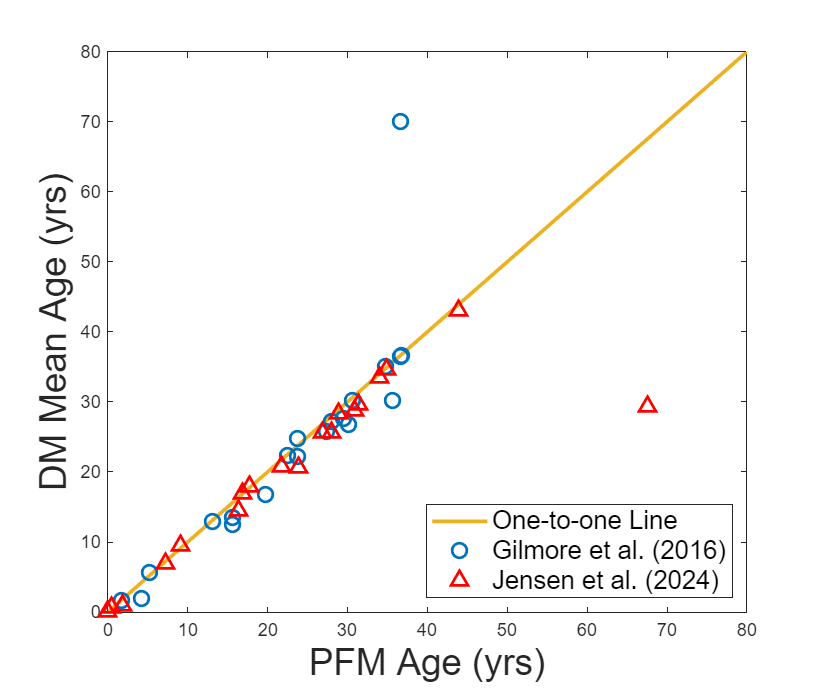


Figure4 = figure('Position',[100 100 600 500]);
plot([0.001 5000],[0.001 5000],'-',LineWidth=2,Color=[0.9290 0.6940 0.1250]); hold on
plot(GilmoreResults(1:20,1),GilmoreResults(1:20,6),'o',MarkerSize=8,Color=[0 0.4470 0.7410],LineWidth=1.5);  
plot(JensenResults(:,1),JensenResults(:,6),'^',MarkerSize=8,MarkerEdgeColor='r',LineWidth=1.5)
% plot(OneTo1,OneTo5PerUp,'--'); plot(OneTo1,OneTo5PerLow,'--')
% text(3,73,'A','FontSize',25,'EdgeColor','k','FontWeight','bold','LineWidth',1)
xlabel("PFM Age (yrs)",'FontSize',20); ylabel("DM Mean Age (yrs)",'FontSize',20); xlim([0 80]); ylim([0 80]); hold on;
legend('One-to-one Line','Gilmore et al. (2016)','Jensen et al. (2024)',Location='SE',FontSize=14);
exportgraphics(Figure4,strcat(Directory,'\',VersionNumb,' Results\Figures\Age.jpg'),'Resolution',600);

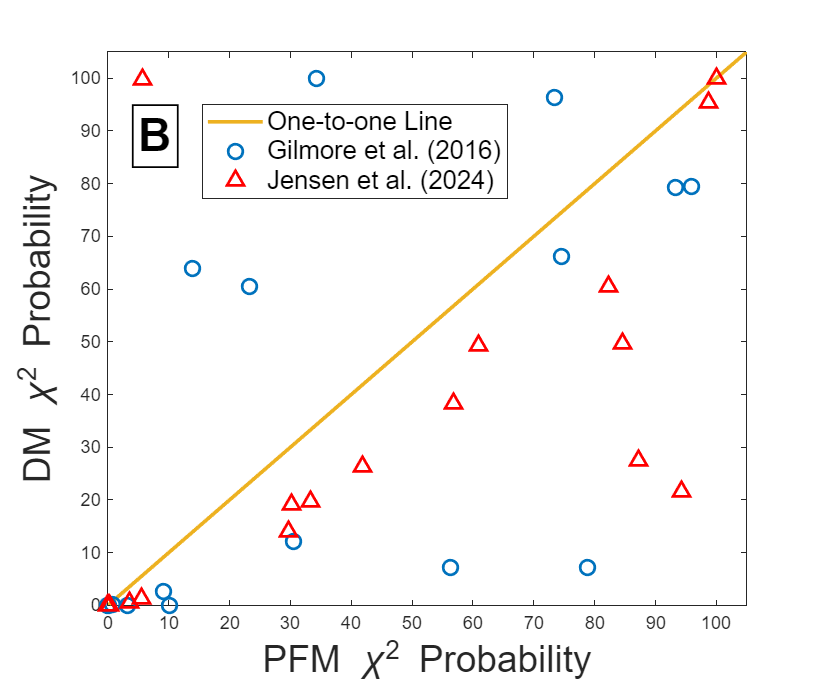

Figure5 = figure('Position',[100 100 600 500]);
plot([0 5000],[0 5000],'-',LineWidth=2,Color=[0.9290 0.6940 0.1250]); hold on
plot(GilmoreResults([1:6,8:11,13,15:18,20],5),GilmoreResults([1:6,8:11,13,15:18,20],11),'o',MarkerSize=8,Color=[0 0.4470 0.7410],LineWidth=1.5); 
plot(JensenResults(1:19,5),JensenResults(1:19,11),'^',MarkerSize=8,MarkerEdgeColor='r',LineWidth=1.5)
% plot(OneTo1,OneTo5PerUp,'--'); plot(OneTo1,OneTo5PerLow,'--')
text(5,89,'B','FontSize',25,'EdgeColor','k','FontWeight','bold','LineWidth',1)
xlabel({"PFM \it\chi\rm^2 Probability"},'FontSize',20); ylabel({"DM \it\chi\rm^2 Probability"},'FontSize',20); xlim([0 105]); ylim([0 105]); hold on;
legend('One-to-one Line','Gilmore et al. (2016)','Jensen et al. (2024)',Position=[0.38 0.73 0.1 0.1],FontSize=14);
hold off;
exportgraphics(Figure5,strcat(Directory,'\',VersionNumb,' Results\Figures\ChiProb.jpg'),'Resolution',600)

G = (GilmoreResults(:,11) + GilmoreResults(:,10))./2

G =                2.820809491
               1.500105856
            1.500000447996
              51.492392425
               1.611581613
               1.524110694
                         0
          1.50000000902335
               33.47051931
              5.0646734765



J = (JensenResults(:,11) + JensenResults(:,10))./2

J =           51.4901114911598
          49.2166007743029
          1.50889005120143
          11.0581168136037
          20.6140614937431
          8.53913037366836
          1.82076818273163
           1.5000000001025
          26.1470684011038
          26.3620427135039


Figure6 = figure('Position',[100 100 600 500]);
plot([0 5000],[0 5000],'-',LineWidth=2,Color=[1 1 1], HandleVisibility='off'); hold on
plot(GilmoreResults(:,6),GilmoreResults(:,7),'o',MarkerSize=8,Color=[0 0.4470 0.7410],LineWidth=1.5); 
plot(JensenResults(:,6),JensenResults(:,7),'^',MarkerSize=8,MarkerEdgeColor='r',LineWidth=1.5)
% plot(OneTo1,OneTo5PerUp,'--'); plot(OneTo1,OneTo5PerLow,'--')
% errorbar(J(:,1),JensenResults(:,6),JensenResults(:,12)./2,"horizontal","LineStyle","none","Color",'k',HandleVisibility='on'); hold on
% errorbar(G(:,1),GilmoreResults(:,6),GilmoreResults(:,12)./2,"horizontal","LineStyle","none","Color",'k',HandleVisibility='off');
text(4,1.5,'B','FontSize',25,'EdgeColor','k','FontWeight','bold','LineWidth',1)
xlabel({"DM Mean Age"},'FontSize',20); ylabel({"Dispersion Parameter"},'FontSize',20); xlim([0 80]); ylim([0 3.2]); hold on;
legend('Gilmore et al. (2016)','Jensen et al. (2024)','1\sigma Age Distribution',Location='SE',FontSize=14); set(gca,'yscale','log');

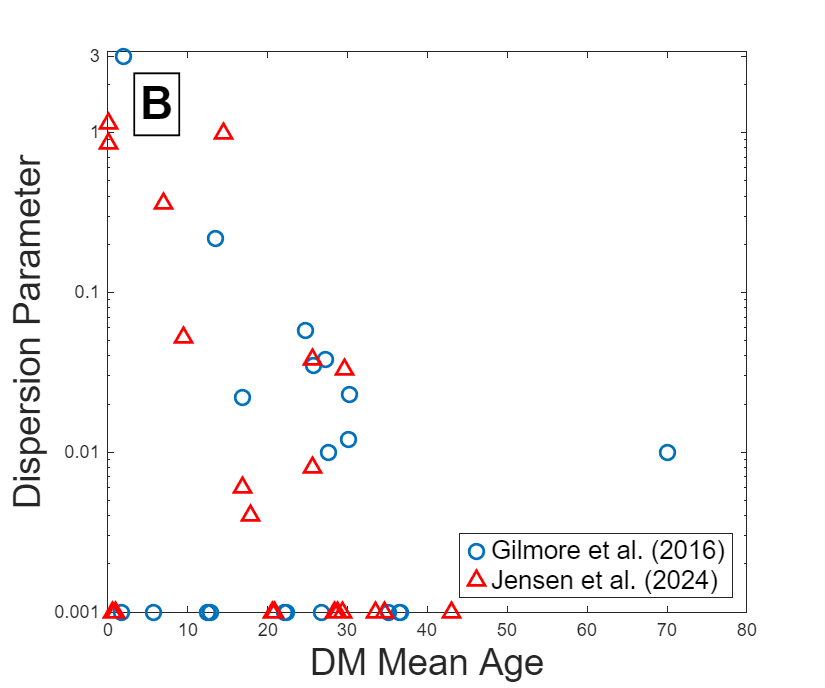

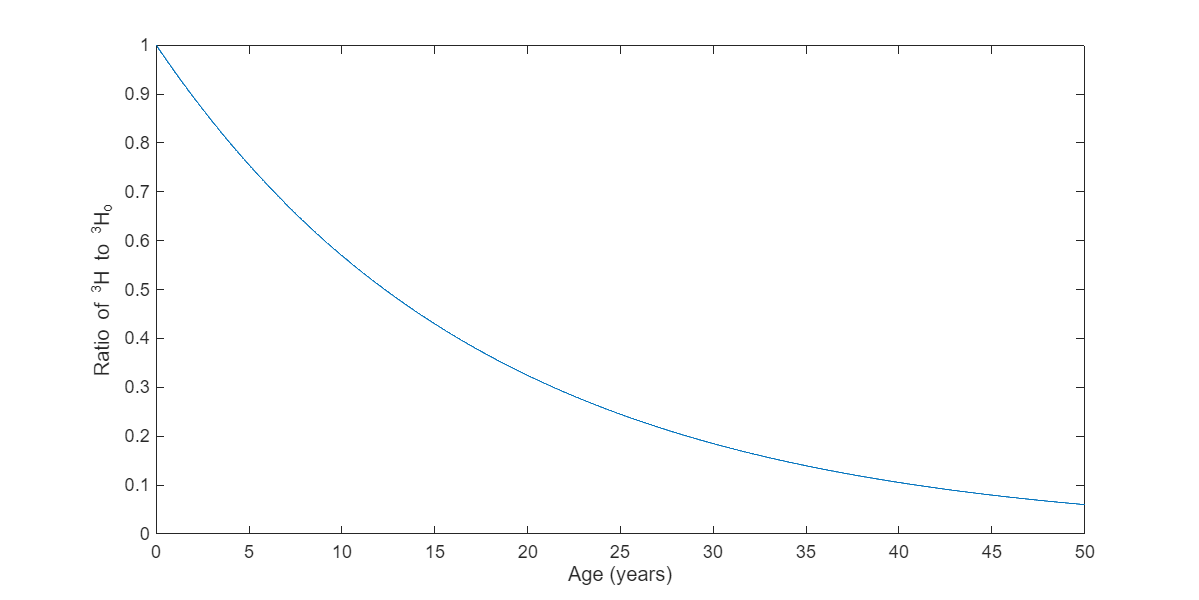

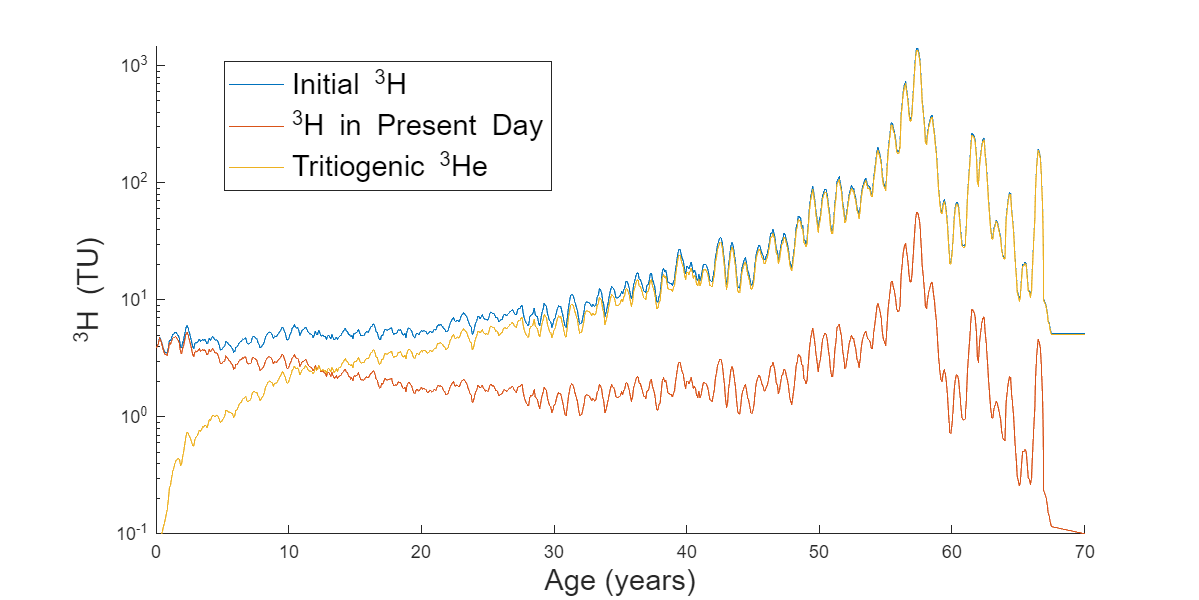

yticks([0.001 0.01 0.1 1 3])
hold off;

exportgraphics(Figure6,strcat(Directory,'\',VersionNumb,' Results\Figures\DP.jpg'),'Resolution',600)

## Central Tendency

Once results have been generated for all samples, the following code can be used to estimate the percent of each best-fit DM TTD that lies within 4 years of the mean age.

load Gilmore2016Samples.mat
datatable1 = Gilmore2016Samples

datatable1 = 20×12 table
       Sample       SampleDate      SF6      SF6Error     Ho      HoError    TritDec    TritError    Hetrit    HetritError    TritRatio    TritRatioError
    ____________    ___________    ______    ________    _____    _______    _______    _________    ______    ___________    _________    ______________

    {'Pt516RB' }    15-Jul-2012    3.3294    0.49942         7      1.75       4.2         1.05        2.8          0.7            0.6            0.15   
    {'Pt516R'  }    15-Jul-2012    2.6542    0.39812       7.9     1.975       1.4         0.35        6

load Jensen2024Samples.mat
    datatable2 = Jensen2024Samples

datatable2 = 20×12 table
     Sample     SampleDate      SF6      SF6Error      Ho      HoError    TritDec    TritError    Hetrit     HetritError    TritRatio    TritRatioError
    ________    ___________    ______    ________    ______    _______    _______    _________    _______    ___________    _________    ______________

    {'68CA'}    19-Oct-2020    8.4646     1.2697     4.8616     1.2154    3.2401      0.81002      1.6215      0.40537       0.66647         0.16662   
    {'250C'}    18-Oct-2020    7.0208     1.0531     4.8769     1.2192    2.9728       0.7432      1.9041     

a(1:20) = table2cell(datatable2(:,1))

a = 1×20 cell array
    {'68CA'}    {'250C'}    {'250R'}    {'328C'}    {'328L'}    {'412C'}    {'489C'}    {'489L'}    {'489R'}    {'KMC'}    {'KMR'}    {'MCC'}    {'MCR'}    {'WC1C'}    {'WC1L'}    {'WC1R'}    {'WC2C'}    {'WC2L'}    {'WC2R'}    {'412R'}


a(21:40) = table2cell(datatable1(:,1))

a = 1×40 cell array
    {'68CA'}    {'250C'}    {'250R'}    {'328C'}    {'328L'}    {'412C'}    {'489C'}    {'489L'}    {'489R'}    {'KMC'}    {'KMR'}    {'MCC'}    {'MCR'}    {'WC1C'}    {'WC1L'}    {'WC1R'}    {'WC2C'}    {'WC2L'}    {'WC2R'}    {'412R'}    {'Pt516RB'}    {'Pt516R'}    {'Pt516C'}    {'Pt516L'}    {'Pt516LB'}    {'Pt481RB'}    {'Pt481R'}    {'Pt481C'}    {'Pt481L'}    {'Pt481LB'}    {'Pt715RB'}    {'Pt715R'}    {'Pt715C'}    {'Pt715L'}    {'Pt715LB'}    {'Pt1260RB'}    {'Pt1260R'}    {'Pt1260C'}    {'Pt1260L'}    {'Pt1260LB'}



b(1:20) = JensenResults(:,22).*100

b =        56.743       84.531       96.866          100          100       98.989       99.036       78.703       36.897       63.882        58.08       99.981       93.478       64.452       98.514       99.781       40.531       13.486            0       94.198


b(10:11) = 100;
b(21:40) = GilmoreResults(:,22).*100

Unrecognized function or variable 'GilmoreResults'.


[sortedb, sortOrder] = sort(b, 'descend')
A = a(sortOrder)

function basicwaitbar
f = waitbar(0,'Please wait...');
pause(.5)

waitbar(.33,f,'Loading your data');
pause(1)

waitbar(.67,f,'Processing your data');
pause(1)

waitbar(1,f,'Finishing');
pause(1)

close(f)
end
